# DL draft

(Single cell, Section 1/2/3)

github@hnxj; github@dynasim

## Initialization

clear;close all;clc;
PathToDynaSim = 'D:\Works\Computational'; % Change it based on your local path for dynasim 
cd(PathToDynaSim);
addpath(genpath('DynaSim'));
cd('DynaSim');

## 1.1: Baseline voltage optimization


$$:N \rightarrow f(r_v ; \nabla E_{leak})$$


RunDuration = 500; % In ms (miliseconds)
study_dir = 'dlModels/HHNS1';

spec = dsCheckSpecification('HH');
vary = {'HH','Eleak',[-70 -60 -50 -40 -30]};
solver_options = {'tspan',[0 RunDuration],'solver','rk1','dt',.01,'compile_flag',0,'verbose_flag',1};
data = dsSimulate(spec,'vary',vary,solver_options{:});


PREPARING STUDY:

PREPARING SOLVER:
Changing directory to D:\Works\Computational\DynaSim\solve
Saving params.mat
Creating solver file: D:\Works\Computational\DynaSim\solve\solve_ode_20230727141127_843.m
Changing directory back to D:\Works\Computational\DynaSim

SIMULATING MODEL:
Solving system using D:\Works\Computational\DynaSim\solve\solve_ode_20230727141127_843.m
Changing directory to D:\Works\Computational\DynaSim\solve
Saving model parameters: D:\Works\Computational\DynaSim\solve\params.mat

Running simulation 1/5 (solver='rk1', dt=0.01, tspan=[0 500]) ...
Total Memory Used <= 1 GB 
Elapsed time: 0.1 seconds.
Changing directory to D:\Works\Computational\DynaSim\solve
Saving model parameters: D:\Works\Computational\DynaSim\solve\params.mat

Running simulation 2/5 (solver='rk1', dt=0.01, tspan=[0 500]) ...
Total Memory Used <= 1 GB 
Elapsed time: 0.1 seconds.
Changing directory to D:\Works\Computational\DynaSim\solve
Saving model parameters: D:\Works\Computational\DynaSim\solve\par

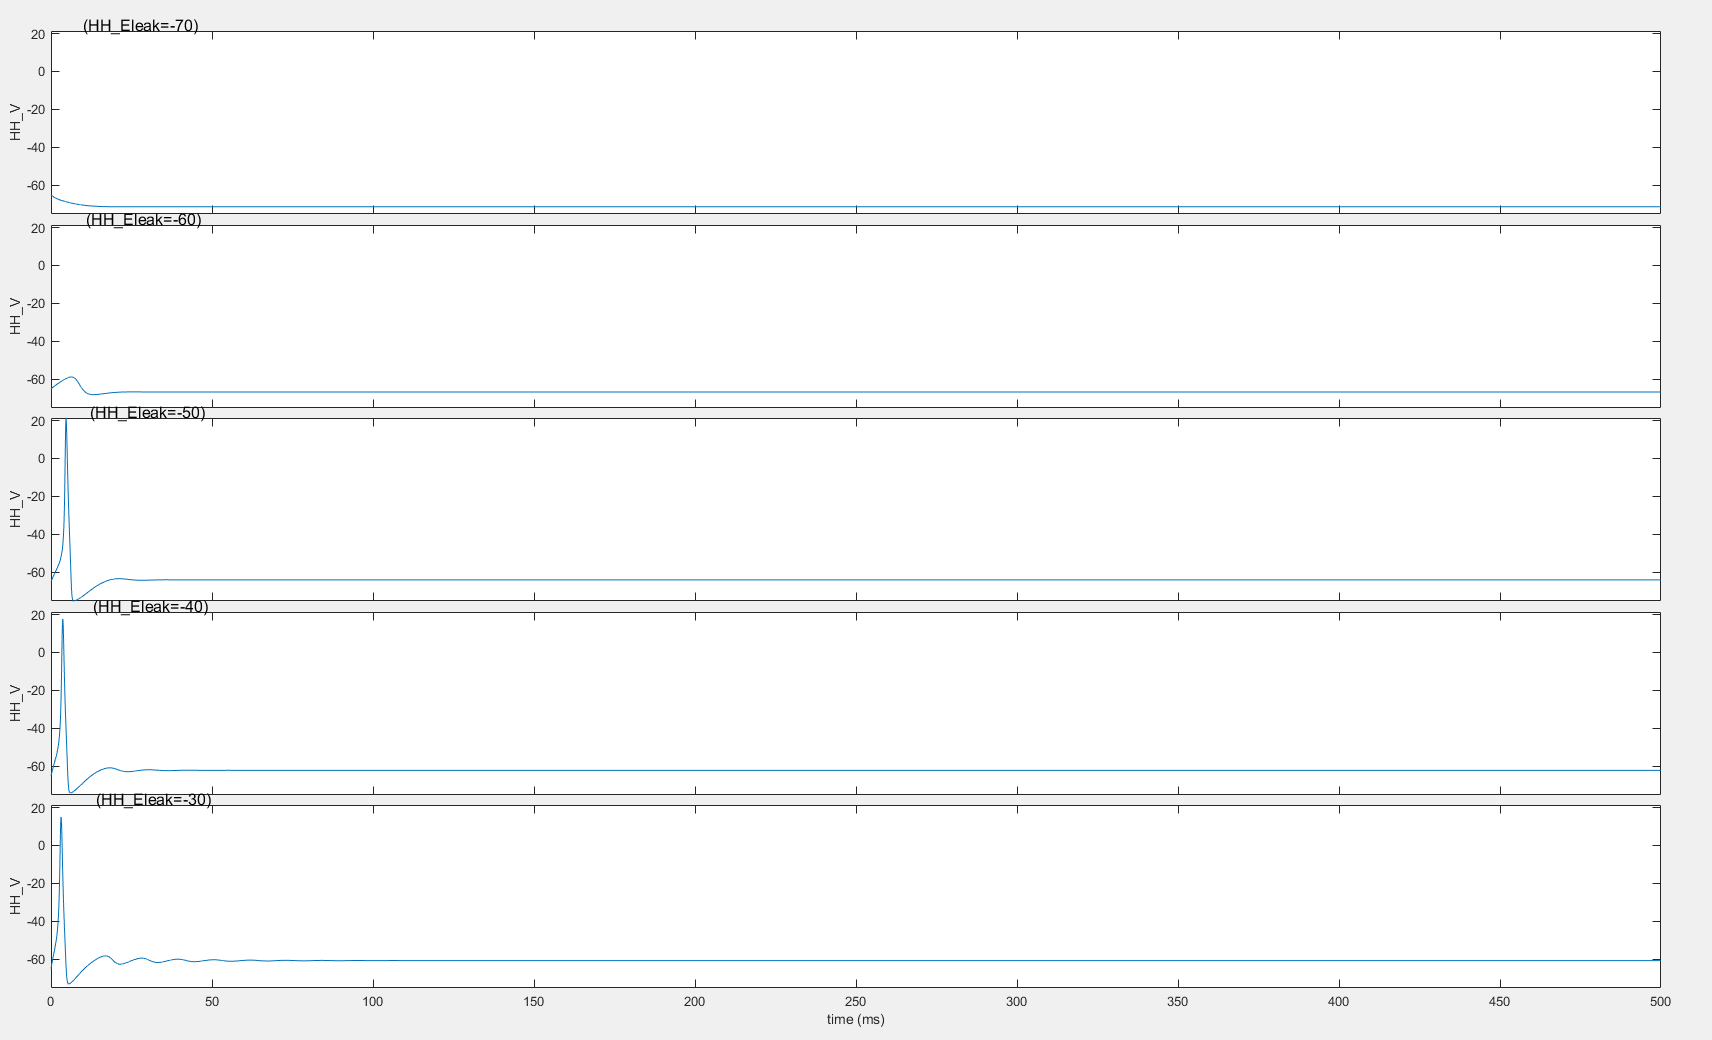

dsPlot(data,'plot_type','waveform');

## Passing to DynaLearn

dl = DynaLearn(spec, study_dir, 'raw', 'HHNS1');



@DS.DL
>Creating DynaLearn model object 
->NOTE: Parallel flag is 0 by default.
-->To change parallel flag, set dlParallelFlag = 0 or 1
->Parallel flag is : 0

-->If you encountered an error related to parallel flag, set dlParallelFlag = 0.

PREPARING STUDY:
Creating study directory: dlModels/HHNS1

PREPARING SOLVER:
Creating solver directory D:\Works\Computational\DynaSim\dlModels\HHNS1\solve
Changing directory to D:\Works\Computational\DynaSim\dlModels\HHNS1\solve
Saving params.mat
Creating solver file: D:\Works\Computational\DynaSim\dlModels\HHNS1\solve\solve_ode_20230626163104_758.m
Changing directory back to D:\Works\Computational\DynaSim

SIMULATING MODEL:
Solving system using D:\Works\Computational\DynaSim\dlModels\HHNS1\solve\solve_ode_20230626163104_758.m
Changing directory to D:\Works\Computational\DynaSim\dlModels\HHNS1\solve
Saving model parameters: D:\Works\Computational\DynaSim\dlModels\HHNS1\solve\params.mat

Running simulation 1/1 (solver='rk1', dt=0.01, tspan=[0 100]

dl.dlSave();


->Model saved in "dlModels/HHNS1/dlFile.mat".


## Load (ONLY IF ALREADY EXISTS)

id = 1; % 1, 2, ...
dl = DynaLearn.dlLoader(char("dlModels/HHNS" + num2str(id)));

DL object loaded from dlModels/HHNS1 
Params.mat file loaded from dlModels/HHNS1 
--------
--->Constructing graph ... Done.

Reinitialized.


param_file = fullfile(study_dir, 'params.mat');
load(param_file, 'p');
fprintf('Initial Eleak: %g\n', p.HH_ileak_Eleak);

Initial Eleak: -54.4


target_RMP = -60;

% Define optimization parameters
dlInputParameters = {dlNullInputs(RunDuration)}; % Null inputs (no external stimulation).
dlOutputParameters = {['HH', '_V'], 1, [100 RunDuration], 'av'}; % 'av' is average voltage
dlTargetParameters = {{'MQE', 1, target_RMP, 1}}; % Format: (1)Mode;(2)Output indices;(3)Target value;(4)Weight in loss equation

% Define training options
dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1e-3; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 1; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.3;
dlTrainOptions('dlTrainIncludeList') = ["_Eleak"];
dlTrainOptions('dlCheckpointCoefficient') = 1.1;
dlTrainOptions('dlUpdateVerbose') = 1;
dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

-> Training started:
-->dlBatchs (batch size) was not determined in options map, default dlBatchs = 1
--->Ignore dlBatchs if your update mode is trial or epoch.

-->Included variable(s) on fitting: 
---> _Eleak
-->Excluded variable(s) on fitting: 
-->No variables were manually excluded in the fitting exclude list.
--->No dynasim variables are excluded by default.
-->Restricted variable(s) on fitting: 
-->No variables were manually restricted in the fitting restrict list.
--->No dynasim variables are restricted by default.
-->Synchronized variable(s) on fitting: 
-->No variables were manually synchronized.
--->No dynasim variables are synchronized by default.
-->Learning rule was not determined in options map
--->Default dlLearningRule = 'GeneralizedStochasticDeltaRule'
-->Update mode was not determined in options map, default dlUpdateMode = 'trial'
-->No custom logs specified; Ignore this if you did not have custom logs.
-->Checkpoint flag was not determined in options map, default dlC

dl.dlSimulate();

Total Memory Used <= 1 GB 
Done.


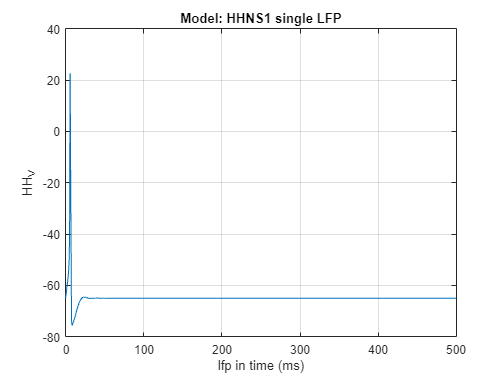

dl.dlPlotAllPotentials('lfp');

fprintf("Initial membrane potential = %f", dl.dlLastOutputs{1});

Initial membrane potential = -64.999722

dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1e-1; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 20; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.5;
dlTrainOptions('dlTrainIncludeList') = ["_Eleak"];
dlTrainOptions('dlCheckpointCoefficient') = 1.5;
dlTrainOptions('dlUpdateVerbose') = 1;
dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

-> Training started:
-->dlBatchs (batch size) was not determined in options map, default dlBatchs = 1
--->Ignore dlBatchs if your update mode is trial or epoch.

-->Included variable(s) on fitting: 
---> _Eleak
-->Excluded variable(s) on fitting: 
-->No variables were manually excluded in the fitting exclude list.
--->No dynasim variables are excluded by default.
-->Restricted variable(s) on fitting: 
-->No variables were manually restricted in the fitting restrict list.
--->No dynasim variables are restricted by default.
-->Synchronized variable(s) on fitting: 
-->No variables were manually synchronized.
--->No dynasim variables are synchronized by default.
-->Learning rule was not determined in options map
--->Default dlLearningRule = 'GeneralizedStochasticDeltaRule'
-->Update mode was not determined in options map, default dlUpdateMode = 'trial'
-->No custom logs specified; Ignore this if you did not have custom logs.
-->Checkpoint flag was not determined in options map, default dlC

-->Log flag for loss plot is not specified; default = 1.


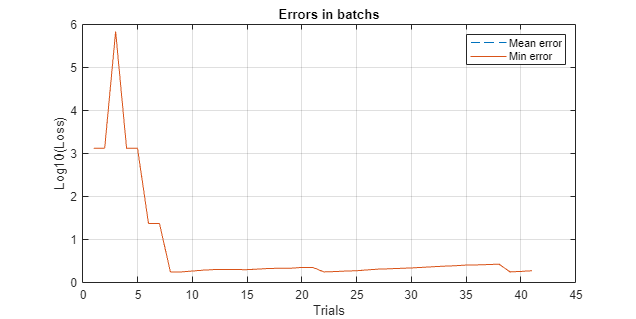


dl.dlPlotBatchErrors(1);

dl.dlLoadOptimal();

		Checkpoint file loaded from dlModels/HHNS1/Optimal 


dl.dlSimulate();

Total Memory Used <= 1 GB 
Done.


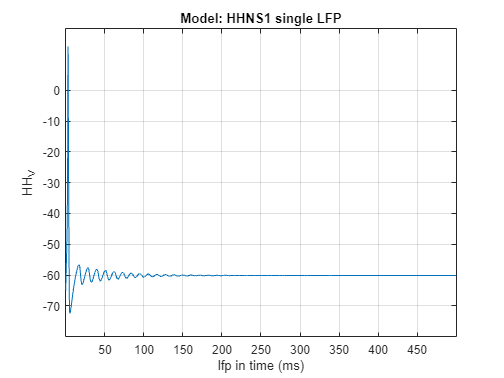

dl.dlPlotAllPotentials('lfp');

fprintf("Final membrane potential = %f", dl.dlLastOutputs{1});

Final membrane potential = -60.163782

optimal_param_file = fullfile(study_dir, 'Optimalparams.mat');
load(optimal_param_file, 'p');
fprintf('Final Eleak: %g\n', p.HH_ileak_Eleak);

Final Eleak: -26.0252


## 1.2: Firing rate optimization


$$:N \rightarrow f(r_{fr} ; \nabla E_{leak}, I_{app})$$


RunDuration = 500; % In ms (miliseconds)
study_dir = 'dlModels/HHNS2';

spec = dsCheckSpecification('HH');
vary = {'HH','Iapp',[-4 -1 0 1 4 7 8.80720 8.80721 8.80741 11 14 17]};
solver_options = {'tspan',[0 RunDuration],'solver','rk1','dt',.01,'compile_flag',0,'verbose_flag',1};
data = dsSimulate(spec,'vary',vary,solver_options{:});


PREPARING STUDY:

PREPARING SOLVER:
Changing directory to D:\Works\Computational\DynaSim\solve
Saving params.mat
Creating solver file: D:\Works\Computational\DynaSim\solve\solve_ode_20230727142652_575.m
Changing directory back to D:\Works\Computational\DynaSim

SIMULATING MODEL:
Solving system using D:\Works\Computational\DynaSim\solve\solve_ode_20230727142652_575.m
Changing directory to D:\Works\Computational\DynaSim\solve
Saving model parameters: D:\Works\Computational\DynaSim\solve\params.mat

Running simulation 1/12 (solver='rk1', dt=0.01, tspan=[0 500]) ...
Total Memory Used <= 1 GB 
Elapsed time: 0.1 seconds.
Changing directory to D:\Works\Computational\DynaSim\solve
Saving model parameters: D:\Works\Computational\DynaSim\solve\params.mat

Running simulation 2/12 (solver='rk1', dt=0.01, tspan=[0 500]) ...
Total Memory Used <= 1 GB 
Elapsed time: 0.1 seconds.
Changing directory to D:\Works\Computational\DynaSim\solve
Saving model parameters: D:\Works\Computational\DynaSim\solve\p

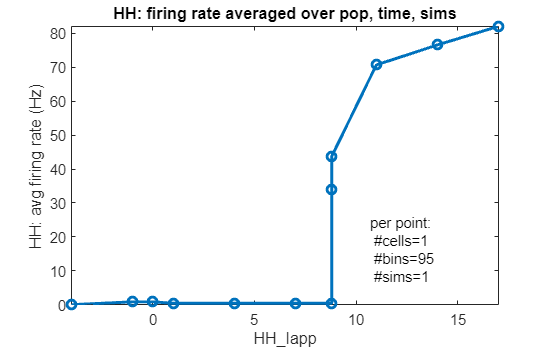

dsPlotFR(data);

## Passing to DynaLearn

dl = DynaLearn(spec, study_dir, 'raw', 'HHNS2');



@DS.DL
>Creating DynaLearn model object 
->NOTE: Parallel flag is 0 by default.
-->To change parallel flag, set dlParallelFlag = 0 or 1
->Parallel flag is : 0

-->If you encountered an error related to parallel flag, set dlParallelFlag = 0.

PREPARING STUDY:
Creating study directory: dlModels/HHNS2

PREPARING SOLVER:
Creating solver directory D:\Works\Computational\DynaSim\dlModels\HHNS2\solve
Changing directory to D:\Works\Computational\DynaSim\dlModels\HHNS2\solve
Saving params.mat
Creating solver file: D:\Works\Computational\DynaSim\dlModels\HHNS2\solve\solve_ode_20230626162313_969.m
Changing directory back to D:\Works\Computational\DynaSim

SIMULATING MODEL:
Solving system using D:\Works\Computational\DynaSim\dlModels\HHNS2\solve\solve_ode_20230626162313_969.m
Changing directory to D:\Works\Computational\DynaSim\dlModels\HHNS2\solve
Saving model parameters: D:\Works\Computational\DynaSim\dlModels\HHNS2\solve\params.mat

Running simulation 1/1 (solver='rk1', dt=0.01, tspan=[0 100]

dl.dlSave();


->Model saved in "dlModels/HHNS2/dlFile.mat".


## Load (ONLY IF ALREADY EXISTS)

id = 2; % 1, 2, ...
dl = DynaLearn.dlLoader(char("dlModels/HHNS" + num2str(id)));

DL object loaded from dlModels/HHNS2 
Params.mat file loaded from dlModels/HHNS2 
--------
--->Constructing graph ... Done.

Reinitialized.


param_file = fullfile(study_dir, 'params.mat');
load(param_file, 'p');
fprintf('Initial Iapp: %g, Eleak: %g\n', p.HH_Iapp, p.HH_ileak_Eleak);

Initial Iapp: 0, Eleak: -54.4


target_FR = 70;

% Define optimization parameters
dlInputParameters = {dlNullInputs(RunDuration)}; % Null inputs (no external stimulation).
dlOutputParameters = {['HH', '_V'], 1, [100 RunDuration], 'afr'}; % 'av' is average voltage
dlTargetParameters = {{'MSE', 1, target_FR, 1}}; % Format: (1)Mode;(2)Output indices;(3)Target value;(4)Weight in loss equation

% Define training options
dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1e-3; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 1; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.3;
dlTrainOptions('dlTrainIncludeList') = ["HH_Iapp", "_Eleak"];
dlTrainOptions('dlTrainRestrictList') = "_Eleak";
dlTrainOptions('dlTrainRestrictCoef') = {.05};
dlTrainOptions('dlCheckpointCoefficient') = 1.1;
dlTrainOptions('dlUpdateVerbose') = 1;
dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

-> Training started:
-->dlBatchs (batch size) was not determined in options map, default dlBatchs = 1
--->Ignore dlBatchs if your update mode is trial or epoch.

-->Included variable(s) on fitting: 
---> HH_Iapp
---> _Eleak
-->Excluded variable(s) on fitting: 
-->No variables were manually excluded in the fitting exclude list.
--->No dynasim variables are excluded by default.
-->Restricted variable(s) on fitting: 
---> _Eleak
-->Synchronized variable(s) on fitting: 
-->No variables were manually synchronized.
--->No dynasim variables are synchronized by default.
-->Learning rule was not determined in options map
--->Default dlLearningRule = 'GeneralizedStochasticDeltaRule'
-->Update mode was not determined in options map, default dlUpdateMode = 'trial'
-->No custom logs specified; Ignore this if you did not have custom logs.
-->Checkpoint flag was not determined in options map, default dlCheckpoint = 'true'
-->ExcludeDiverge was not determined in options map, default dlExcludeDiverge =

dl.dlSimulate();

Total Memory Used <= 1 GB 
Done.


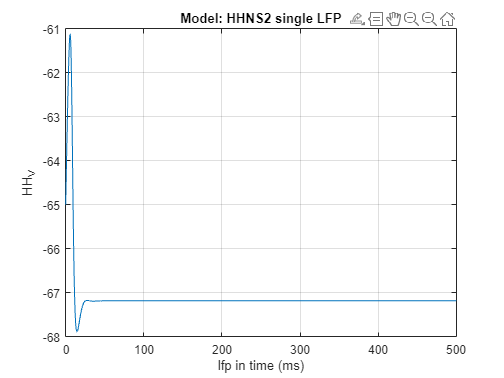

dl.dlPlotAllPotentials('lfp');

fprintf("Initial membrane potential = %f", dl.dlLastOutputs{1});

Initial membrane potential = 0.000000

dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1e+0; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 20; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.0;
dlTrainOptions('dlTrainIncludeList') = ["HH_Iapp", "_Eleak"];
dlTrainOptions('dlTrainRestrictList') = "_Eleak";
dlTrainOptions('dlTrainRestrictCoef') = {.05};
dlTrainOptions('dlCheckpointCoefficient') = 2.0;
dlTrainOptions('dlUpdateVerbose') = 1;
dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

-> Training started:
-->dlBatchs (batch size) was not determined in options map, default dlBatchs = 1
--->Ignore dlBatchs if your update mode is trial or epoch.

-->Included variable(s) on fitting: 
---> HH_Iapp
---> _Eleak
-->Excluded variable(s) on fitting: 
-->No variables were manually excluded in the fitting exclude list.
--->No dynasim variables are excluded by default.
-->Restricted variable(s) on fitting: 
---> _Eleak
-->Synchronized variable(s) on fitting: 
-->No variables were manually synchronized.
--->No dynasim variables are synchronized by default.
-->Learning rule was not determined in options map
--->Default dlLearningRule = 'GeneralizedStochasticDeltaRule'
-->Update mode was not determined in options map, default dlUpdateMode = 'trial'
-->No custom logs specified; Ignore this if you did not have custom logs.
-->Checkpoint flag was not determined in options map, default dlCheckpoint = 'true'
-->ExcludeDiverge was not determined in options map, default dlExcludeDiverge =

-->Log flag for loss plot is not specified; default = 1.


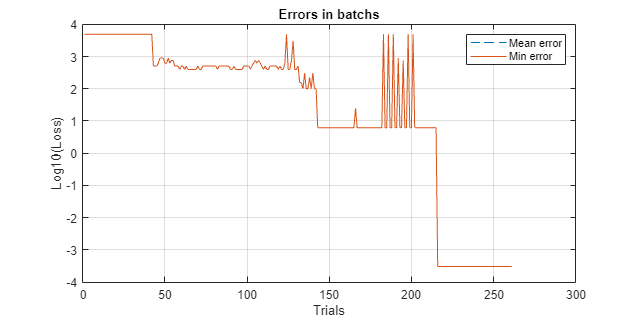


dl.dlPlotBatchErrors(1);

dl.dlLoadOptimal();

		Checkpoint file loaded from dlModels/HHNS2/Optimal 


dl.dlSimulate();

Total Memory Used <= 1 GB 
Done.


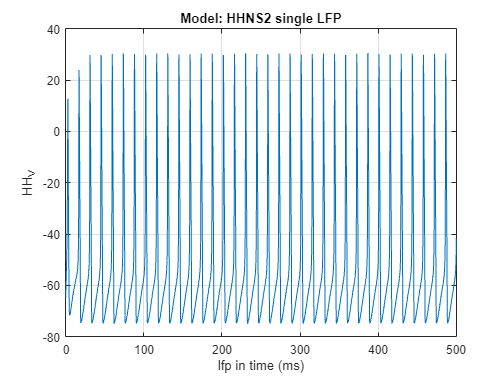

dl.dlPlotAllPotentials('lfp');

fprintf("Final aFR = %f", dl.dlLastOutputs{1});

Final aFR = 69.982504

optimal_param_file = fullfile(study_dir, 'Optimalparams.mat');
load(optimal_param_file, 'p');
fprintf('Final Iapp: %g, Eleak: %g\n', p.HH_Iapp, p.HH_ileak_Eleak);

Final Iapp: 11.0354, Eleak: -55.1589


## 2.1: Populatin baseline voltage optimization


$$:N \rightarrow f(r_v ; \nabla E_{leak})$$


RunDuration = 500; % In ms (miliseconds)
study_dir = 'dlModels/HHNS3';

eqns={
  'dV/dt=Iapp+@current+noise*randn(1,N_pop); Iapp=0; noise=0'
};

Iapp = 10;

gGABAfast = .1;
gAMPA = .1;

tauGABAfast = 5;
tauAMPA = 2;

s=[];
s.populations(1).name='ES';
s.populations(1).size=80;
s.populations(1).equations=eqns;
s.populations(1).mechanism_list={'iNa','iK'};
s.populations(1).parameters={'Iapp',Iapp,'gNa',120,'gK',36,'noise', 40};

s.populations(2).name='INfast';
s.populations(2).size=20;
s.populations(2).equations=eqns;
s.populations(2).mechanism_list={'iNa','iK'};
s.populations(2).parameters={'Iapp',0,'gNa',120,'gK',36,'noise', 40};

s.connections(1).direction='INfast->ES';
s.connections(1).mechanism_list={'iGABAa'};
s.connections(1).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast};

s.connections(2).direction='ES->INfast';
s.connections(2).mechanism_list={'iAMPA'};
s.connections(2).parameters={'tauD',tauAMPA,'gAMPA',gAMPA};

s.connections(3).direction='INfast->INfast';
s.connections(3).mechanism_list={'iGABAa'};
s.connections(3).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast};

## Passing to DynaLearn

dl = DynaLearn(s, study_dir, 'mex', 'HHNS3', 1);



@DS.DL
>Creating DynaLearn model object 
->NOTE: Parallel flag is 0 by default.
-->To change parallel flag, set dlParallelFlag = 0 or 1
->Parallel flag is : 1

-->If you encountered an error related to parallel flag, set dlParallelFlag = 0.

PREPARING STUDY:
Creating study directory: D:\Works\Computational\DynaSim\dlModels\HHNS3
Creating data directory: D:\Works\Computational\DynaSim\dlModels\HHNS3\data
Creating results directory: D:\Works\Computational\DynaSim\dlModels\HHNS3\results
saving study file: D:\Works\Computational\DynaSim\dlModels\HHNS3\studyinfo.mat

PREPARING SOLVER:
Creating solver directory D:\Works\Computational\DynaSim\dlModels\HHNS3\solve\sim1
Changing directory to D:\Works\Computational\DynaSim\dlModels\HHNS3\solve\sim1
Saving params.mat
Creating solver file: D:\Works\Computational\DynaSim\dlModels\HHNS3\solve\sim1\solve_ode_20230627183515_966.m
Compiling file: D:\Works\Computational\DynaSim\dlModels\HHNS3\solve\sim1\solve_ode_20230627183515_966.m
            to: D


Parallel simulations complete.

--------
--->Constructing graph ... Done.

@DS.DL:DynaLearn model created.


dl.dlSave();


->Model saved in "dlModels/HHNS3/dlFile.mat".


## Load (ONLY IF ALREADY EXISTS)

id = 3; % 1, 2, ...
dl = DynaLearn.dlLoader(char("dlModels/HHNS" + num2str(id)));

DL object loaded from dlModels/HHNS3 
Params.mat file loaded from dlModels/HHNS3 
--------
--->Constructing graph ... Done.

Reinitialized.


param_file = fullfile(study_dir, 'params.mat');
load(param_file, 'p');
fprintf('Initial TauD(IN): %g, ES_Noise = %g, INF_Noise = %g\n', p.ES_INfast_iGABAa_tauD, p.ES_noise, p.INfast_noise);

Initial TauD(IN): 5, ES_Noise = 40, INF_Noise = 40


target_FRQ = 70; % Hz
target_AV = -58; % mV

dlInputParameters = {dlNullInputs(RunDuration)}; % Null inputs (no external stimulation).
dlOutputParameters = [{['ES', '_V'], 1:80, [10 RunDuration], 'afr'}; {['ES', '_V'], 1:80, [10 RunDuration], 'av'}];
dlTargetParameters = {[{'MSE', 1, target_FRQ, 1}; {'MSE', 2, -58, 1}]}; % Format: (1)Mode;(2)Output indices;(3)Target value;(4)Weight in loss equation

% Define training options
dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1e-5; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 1; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.4;

dlTrainOptions('dlExcludeDiverge') = 0; % Exclude non-optimals from model log
dlTrainOptions('dlCheckpointLengthCap') = 11;
dlTrainOptions('dlUpdateVerbose') = 1;
dlTrainOptions('dlTrainIncludeList') = ["ES_INfast_iGABAa_tauD", "ES_noise", "INfast_noise"];

dlTrainOptions('dlTrainRestrictList') = ["ES_noise", "INfast_noise"]; % Restrict list
dlTrainOptions('dlTrainRestrictCoef') = {.001, .001}; % Restrict coeffs
dlTrainOptions('dlTrainSyncList') = [["ES_INfast_iGABAa_tauD", ...
    "INfast_INfast_iGABAa_tauD"]; ["ES_noise", "INfast_noise"]]; % Each array row will be overrided
                                  % by synchronizing to the first element
dlTrainOptions('dlCheckpointCoefficient') = 1.5;

dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

-> Training started:
-->dlBatchs (batch size) was not determined in options map, default dlBatchs = 1
--->Ignore dlBatchs if your update mode is trial or epoch.

-->Included variable(s) on fitting: 
---> ES_INfast_iGABAa_tauD
---> ES_noise
---> INfast_noise
-->Excluded variable(s) on fitting: 
-->No variables were manually excluded in the fitting exclude list.
--->No dynasim variables are excluded by default.
-->Restricted variable(s) on fitting: 
---> ES_noise
---> INfast_noise
-->Synchronized variable(s) on fitting: 
--->N.1:     "ES_INfast_iGABAa_tauD"    "INfast_INfast_iGABAa_tauD"

--->N.2:     "ES_noise"    "INfast_noise"

---->NOTE: SyncList format should be group(row)Xvariables(column).
---->On each group, All variables will be set to be equal to the first one.

-->Learning rule was not determined in options map
--->Default dlLearningRule = 'GeneralizedStochasticDeltaRule'
-->Update mode was not determined in options map, default dlUpdateMode = 'trial'
-->No custom logs specifi

dl.dlSimulate();

Done.


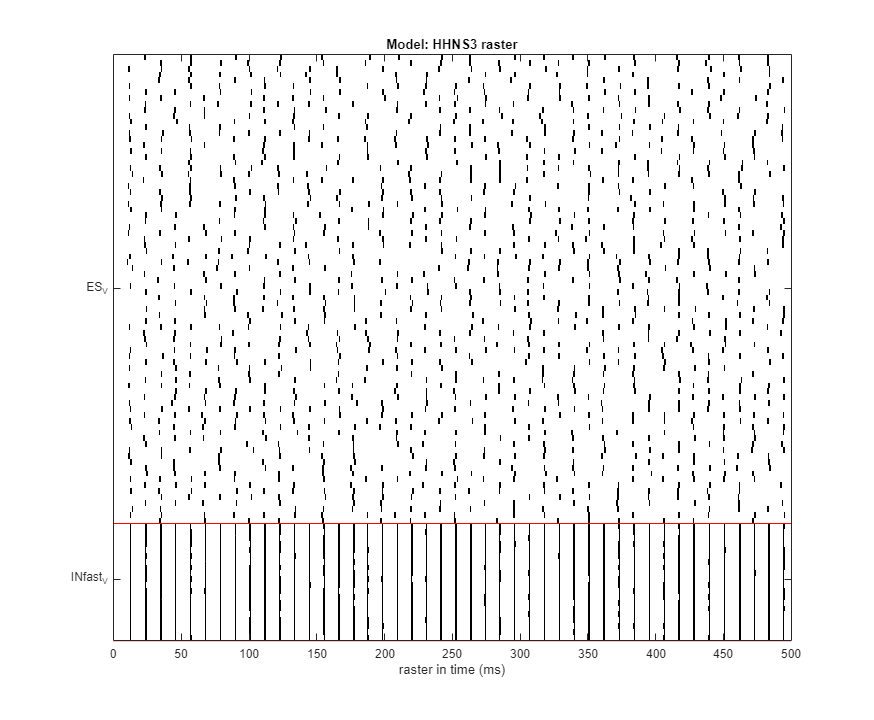

dl.dlPlotAllPotentials('raster');

fprintf("Initial firing rate = %f, membrane potential = %f\n", dl.dlLastOutputs{1}, dl.dlLastOutputs{2});

Initial firing rate = 34.839829, membrane potential = -63.948922


dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1e-3; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 100; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.4;

dlTrainOptions('dlExcludeDiverge') = 0; % Exclude non-optimals from model log
dlTrainOptions('dlCheckpointLengthCap') = 11;
dlTrainOptions('dlUpdateVerbose') = 1;
dlTrainOptions('dlTrainIncludeList') = ["ES_INfast_iGABAa_tauD", "ES_noise"];

dlTrainOptions('dlTrainRestrictList') = ["ES_noise", "INfast_noise"]; % Restrict list
dlTrainOptions('dlTrainRestrictCoef') = {.001, .001}; % Restrict coeffs
dlTrainOptions('dlTrainSyncList') = [["ES_INfast_iGABAa_tauD", ...
    "INfast_INfast_iGABAa_tauD"]; ["ES_noise", "INfast_noise"]]; % Each array row will be overrided
                                  % by synchronizing to the first element
dlTrainOptions('dlCheckpointCoefficient') = 1.4;

dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

-> Training started:
-->dlBatchs (batch size) was not determined in options map, default dlBatchs = 1
--->Ignore dlBatchs if your update mode is trial or epoch.

-->Included variable(s) on fitting: 
---> ES_INfast_iGABAa_tauD
---> ES_noise
-->Excluded variable(s) on fitting: 
-->No variables were manually excluded in the fitting exclude list.
--->No dynasim variables are excluded by default.
-->Restricted variable(s) on fitting: 
---> ES_noise
---> INfast_noise
-->Synchronized variable(s) on fitting: 
--->N.1:     "ES_INfast_iGABAa_tauD"    "INfast_INfast_iGABAa_tauD"

--->N.2:     "ES_noise"    "INfast_noise"

---->NOTE: SyncList format should be group(row)Xvariables(column).
---->On each group, All variables will be set to be equal to the first one.

-->Learning rule was not determined in options map
--->Default dlLearningRule = 'GeneralizedStochasticDeltaRule'
-->Update mode was not determined in options map, default dlUpdateMode = 'trial'
-->No custom logs specified; Ignore this if


dl.dlPlotBatchErrors(1);

-->Log flag for loss plot is not specified; default = 1.


dl.dlLoadOptimal();

		Checkpoint file loaded from dlModels/HHNS3/Optimal 
---->Optimal [Parallel]


dl.dlSimulate();

Done.


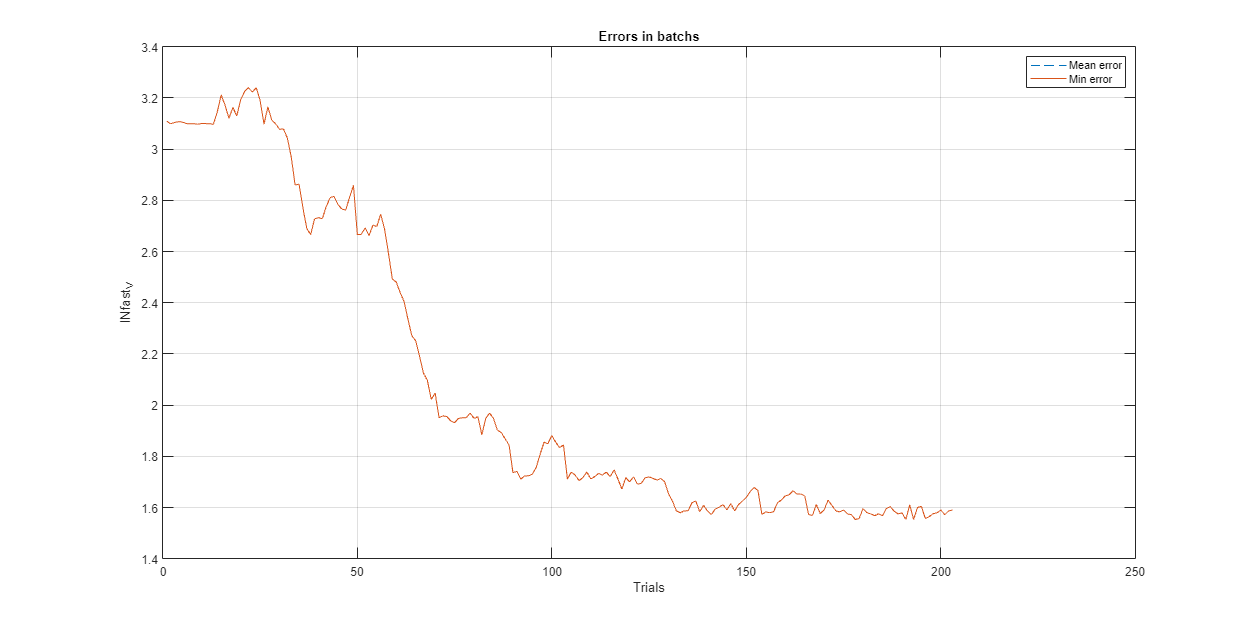

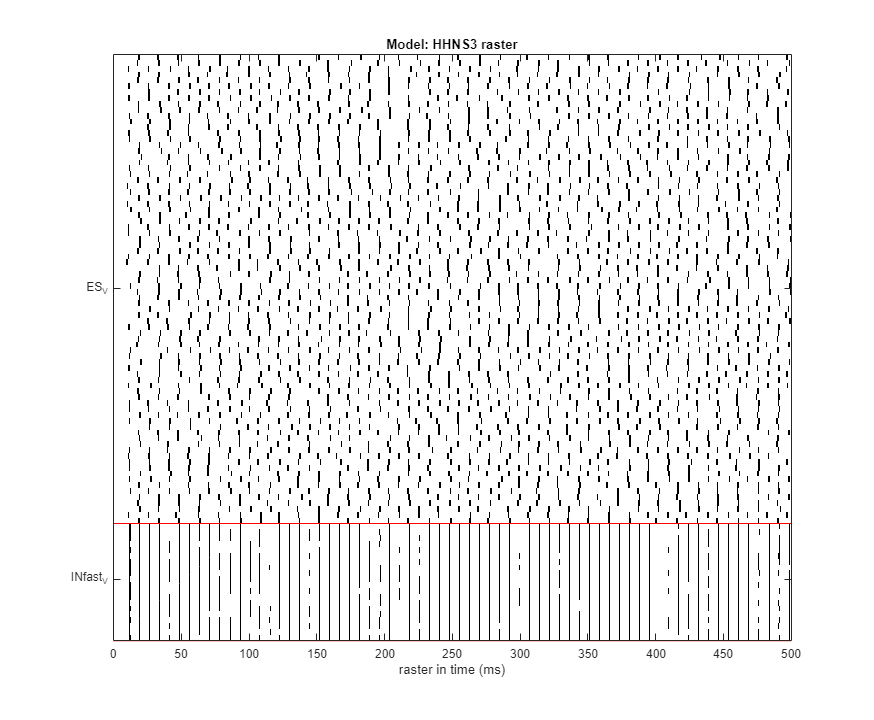

dl.dlPlotAllPotentials('raster');


fprintf("Final firing rate = %f, membrane potential = %f\n", dl.dlLastOutputs{1}, dl.dlLastOutputs{2});

Final firing rate = 63.839012, membrane potential = -58.980453


optimal_param_file = fullfile(study_dir, 'Optimalparams.mat');
load(optimal_param_file, 'p');
fprintf('Final TauD(IN): %g, ES_Noise = %g, INF_Noise = %g\n', p.ES_INfast_iGABAa_tauD, p.ES_noise, p.INfast_noise);

Final TauD(IN): 1.5559, ES_Noise = 39.9985, INF_Noise = 39.9985


## 2.2: Populatin firing rate optimization


$$:N \rightarrow f(r_{fr} ; \nabla E_{leak}, I_{app})$$


RunDuration = 500; % In ms (miliseconds)
study_dir = 'dlModels/HHNS4';

eqns={
  'dV/dt=Iapp+@current+noise*randn(1,N_pop); Iapp=0; noise=0'
};

Iapp = 10;

gGABAfast = .1;
gAMPA = .1;

tauGABAfast = 5;
tauAMPA = 2;

s=[];
s.populations(1).name='ES';
s.populations(1).size=80;
s.populations(1).equations=eqns;
s.populations(1).mechanism_list={'iNa','iK'};
s.populations(1).parameters={'Iapp',Iapp,'gNa',120,'gK',36,'noise', 40};

s.populations(2).name='INfast';
s.populations(2).size=20;
s.populations(2).equations=eqns;
s.populations(2).mechanism_list={'iNa','iK'};
s.populations(2).parameters={'Iapp',0,'gNa',120,'gK',36,'noise', 40};

s.connections(1).direction='INfast->ES';
s.connections(1).mechanism_list={'iGABAa'};
s.connections(1).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast};

s.connections(2).direction='ES->INfast';
s.connections(2).mechanism_list={'iAMPA'};
s.connections(2).parameters={'tauD',tauAMPA,'gAMPA',gAMPA};

s.connections(3).direction='INfast->INfast';
s.connections(3).mechanism_list={'iGABAa'};
s.connections(3).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast};

## Passing to DynaLearn

dl = DynaLearn(s, study_dir, 'mex', 'HHNS4', 1);



@DS.DL
>Creating DynaLearn model object 
->NOTE: Parallel flag is 0 by default.
-->To change parallel flag, set dlParallelFlag = 0 or 1
->Parallel flag is : 1

-->If you encountered an error related to parallel flag, set dlParallelFlag = 0.

PREPARING STUDY:
Creating study directory: D:\Works\Computational\DynaSim\dlModels\HHNS4
Creating data directory: D:\Works\Computational\DynaSim\dlModels\HHNS4\data
Creating results directory: D:\Works\Computational\DynaSim\dlModels\HHNS4\results
saving study file: D:\Works\Computational\DynaSim\dlModels\HHNS4\studyinfo.mat
Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 12 workers.

PREPARING SOLVER:
Creating solver directory D:\Works\Computational\DynaSim\dlModels\HHNS4\solve\sim1
Changing directory to D:\Works\Computational\DynaSim\dlModels\HHNS4\solve\sim1
Saving params.mat
Creating solver file: D:\Works\Computational\DynaSim\dlModels\HHNS4\solve\sim1\solve_ode_20230703110648_393.m
Compiling 


Parallel simulations complete.

--------
--->Constructing graph ... Done.

@DS.DL:DynaLearn model created.


dl.dlSave();


->Model saved in "dlModels/HHNS4/dlFile.mat".


## Load (ONLY IF ALREADY EXISTS)

id = 4; % 1, 2, ...
dl = DynaLearn.dlLoader(char("dlModels/HHNS" + num2str(id)));

DL object loaded from dlModels/HHNS4 
Params.mat file loaded from dlModels/HHNS4 
--------
--->Constructing graph ... Done.

Reinitialized.


param_file = fullfile(study_dir, 'params.mat');
load(param_file, 'p');
fprintf('Initial TauD(IN): %g, ES_Noise = %g, INF_Noise = %g\n', p.ES_INfast_iGABAa_tauD, p.ES_noise, p.INfast_noise);

Initial TauD(IN): 5, ES_Noise = 40, INF_Noise = 40


target_FRQ = 20; % Hz
target_FRQ2 = 70; % mV

dlInputParameters = {dlNullInputs(RunDuration)}; % Null inputs (no external stimulation).
dlOutputParameters = [{['ES', '_V'], 1:80, [10 RunDuration], 'afr'}; {['INfast', '_V'], 1:20, [10 RunDuration], 'afr'}];
dlTargetParameters = {[{'MSE', 1, target_FRQ, 1}; {'MSE', 2, target_FRQ2, 1}]}; % Format: (1)Mode;(2)Output indices;(3)Target value;(4)Weight in loss equation

% Define training options
dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1e-5; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 1; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.4;

dlTrainOptions('dlExcludeDiverge') = 0; % Exclude non-optimals from model log
dlTrainOptions('dlCheckpointLengthCap') = 11;
dlTrainOptions('dlUpdateVerbose') = 1;
dlTrainOptions('dlTrainIncludeList') = ["ES_INfast_iGABAa_tauD", "ES_noise", "INfast_noise"];

dlTrainOptions('dlTrainRestrictList') = ["ES_noise", "INfast_noise"]; % Restrict list
dlTrainOptions('dlTrainRestrictCoef') = {.001, .001}; % Restrict coeffs
dlTrainOptions('dlTrainSyncList') = [["ES_INfast_iGABAa_tauD", ...
    "INfast_INfast_iGABAa_tauD"]; ["ES_noise", "INfast_noise"]]; % Each array row will be overrided
                                  % by synchronizing to the first element
dlTrainOptions('dlCheckpointCoefficient') = 1.5;

dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

-> Training started:
-->dlBatchs (batch size) was not determined in options map, default dlBatchs = 1
--->Ignore dlBatchs if your update mode is trial or epoch.

-->Included variable(s) on fitting: 
---> ES_INfast_iGABAa_tauD
---> ES_noise
---> INfast_noise
-->Excluded variable(s) on fitting: 
-->No variables were manually excluded in the fitting exclude list.
--->No dynasim variables are excluded by default.
-->Restricted variable(s) on fitting: 
---> ES_noise
---> INfast_noise
-->Synchronized variable(s) on fitting: 
--->N.1:     "ES_INfast_iGABAa_tauD"    "INfast_INfast_iGABAa_tauD"

--->N.2:     "ES_noise"    "INfast_noise"

---->NOTE: SyncList format should be group(row)Xvariables(column).
---->On each group, All variables will be set to be equal to the first one.

-->Learning rule was not determined in options map
--->Default dlLearningRule = 'GeneralizedStochasticDeltaRule'
-->Update mode was not determined in options map, default dlUpdateMode = 'trial'
-->No custom logs specifi

dl.dlSimulate();

Done.


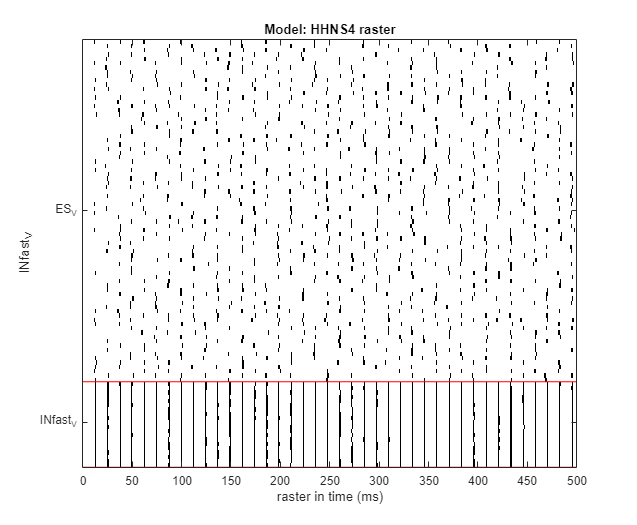

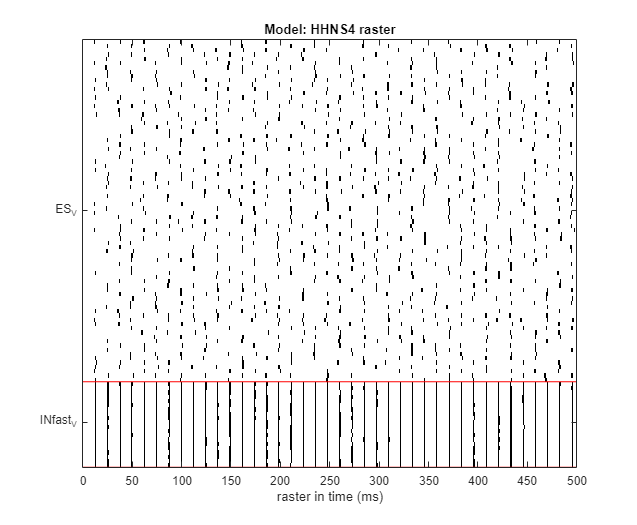

dl.dlPlotAllPotentials('raster');

fprintf("Initial firing rate ES = %f, INfast = %f\n", dl.dlLastOutputs{1}, dl.dlLastOutputs{2});

Initial firing rate ES = 27.774944, INfast = 81.615997


dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1e-3; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 10; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.25;

dlTrainOptions('dlExcludeDiverge') = 0; % Exclude non-optimals from model log
dlTrainOptions('dlCheckpointLengthCap') = 11;
dlTrainOptions('dlUpdateVerbose') = 1;
dlTrainOptions('dlTrainIncludeList') = ["ES_INfast_iGABAa_tauD", "ES_noise"];

dlTrainOptions('dlTrainRestrictList') = ["ES_noise", "INfast_noise"]; % Restrict list
dlTrainOptions('dlTrainRestrictCoef') = {.001, .001}; % Restrict coeffs
dlTrainOptions('dlTrainSyncList') = [["ES_INfast_iGABAa_tauD", ...
    "INfast_INfast_iGABAa_tauD"]; ["ES_noise", "INfast_noise"]]; % Each array row will be overrided
                                  % by synchronizing to the first element
dlTrainOptions('dlCheckpointCoefficient') = 1.1;

dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

-> Training started:
-->dlBatchs (batch size) was not determined in options map, default dlBatchs = 1
--->Ignore dlBatchs if your update mode is trial or epoch.

-->Included variable(s) on fitting: 
---> ES_INfast_iGABAa_tauD
---> ES_noise
-->Excluded variable(s) on fitting: 
-->No variables were manually excluded in the fitting exclude list.
--->No dynasim variables are excluded by default.
-->Restricted variable(s) on fitting: 
---> ES_noise
---> INfast_noise
-->Synchronized variable(s) on fitting: 
--->N.1:     "ES_INfast_iGABAa_tauD"    "INfast_INfast_iGABAa_tauD"

--->N.2:     "ES_noise"    "INfast_noise"

---->NOTE: SyncList format should be group(row)Xvariables(column).
---->On each group, All variables will be set to be equal to the first one.

-->Learning rule was not determined in options map
--->Default dlLearningRule = 'GeneralizedStochasticDeltaRule'
-->Update mode was not determined in options map, default dlUpdateMode = 'trial'
-->No custom logs specified; Ignore this if


dl.dlPlotBatchErrors(1);

-->Log flag for loss plot is not specified; default = 1.


dl.dlLoadOptimal();

		Checkpoint file loaded from dlModels/HHNS4/Optimal 
---->Optimal [Parallel]


dl.dlSimulate();

Done.


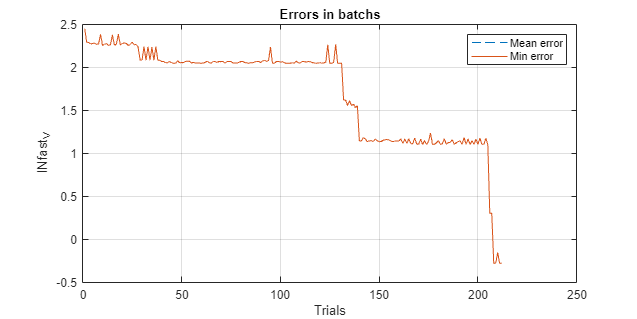

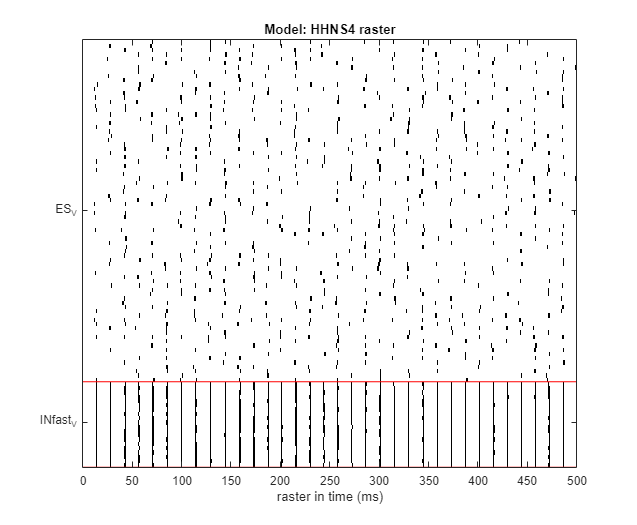

dl.dlPlotAllPotentials('raster');


fprintf("Final firing rate ES = %f, INfast = %f\n", dl.dlLastOutputs{1}, dl.dlLastOutputs{2});

Final firing rate ES = 19.638849, INfast = 69.373597


optimal_param_file = fullfile(study_dir, 'Optimalparams.mat');
load(optimal_param_file, 'p');
fprintf('Final TauD(IN): %g, ES_Noise = %g, INF_Noise = %g\n', p.ES_INfast_iGABAa_tauD, p.ES_noise, p.INfast_noise);

Final TauD(IN): 8.22409, ES_Noise = 40.0005, INF_Noise = 40.0005


## 2.3: Natural frequency optimization


$$:N \rightarrow f(<R,\omega_{Natural}>; \nabla I_{app}, Noise)$$


RunDuration = 500; % In ms (miliseconds)
study_dir = 'dlModels/HHNS6';

eqns={
  'dV/dt=Iapp+@current+noise*randn(1,N_pop); Iapp=0; noise=0'
};

Iapp = 10;

gGABAfast = .1;
gAMPA = .1;

tauGABAfast = 5;
tauAMPA = 2;

s=[];
s.populations(1).name='ES';
s.populations(1).size=80;
s.populations(1).equations=eqns;
s.populations(1).mechanism_list={'iNa','iK'};
s.populations(1).parameters={'Iapp',Iapp,'gNa',120,'gK',36,'noise', 40};

s.populations(2).name='INfast';
s.populations(2).size=20;
s.populations(2).equations=eqns;
s.populations(2).mechanism_list={'iNa','iK'};
s.populations(2).parameters={'Iapp',0,'gNa',120,'gK',36,'noise', 40};

s.connections(1).direction='INfast->ES';
s.connections(1).mechanism_list={'iGABAa'};
s.connections(1).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast};

s.connections(2).direction='ES->INfast';
s.connections(2).mechanism_list={'iAMPA'};
s.connections(2).parameters={'tauD',tauAMPA,'gAMPA',gAMPA};

s.connections(3).direction='INfast->INfast';
s.connections(3).mechanism_list={'iGABAa'};
s.connections(3).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast};

## Passing to DynaLearn

dl = DynaLearn(s, study_dir, 'mex', 'HHNS6', 1);



@DS.DL
>Creating DynaLearn model object 
->NOTE: Parallel flag is 0 by default.
-->To change parallel flag, set dlParallelFlag = 0 or 1
->Parallel flag is : 1

-->If you encountered an error related to parallel flag, set dlParallelFlag = 0.

PREPARING STUDY:
Creating study directory: D:\Works\Computational\DynaSim\dlModels\HHNS6
Creating data directory: D:\Works\Computational\DynaSim\dlModels\HHNS6\data
Creating results directory: D:\Works\Computational\DynaSim\dlModels\HHNS6\results
saving study file: D:\Works\Computational\DynaSim\dlModels\HHNS6\studyinfo.mat
Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 12 workers.

PREPARING SOLVER:
Creating solver directory D:\Works\Computational\DynaSim\dlModels\HHNS6\solve\sim1
Changing directory to D:\Works\Computational\DynaSim\dlModels\HHNS6\solve\sim1
Saving params.mat
Creating solver file: D:\Works\Computational\DynaSim\dlModels\HHNS6\solve\sim1\solve_ode_20230731085138_449.m
Compiling 


Parallel simulations complete.

--------
--->Constructing graph ... Done.

@DS.DL:DynaLearn model created.


dl.dlSave();


->Model saved in "dlModels/HHNS6/dlFile.mat".


## Load (ONLY IF ALREADY EXISTS)

id = 6; % 1, 2, ...
dl = DynaLearn.dlLoader(char("dlModels/HHNS" + num2str(id)));

DL object loaded from dlModels/HHNS6 
Params.mat file loaded from dlModels/HHNS6 
--------
--->Constructing graph ... Done.

Reinitialized.


param_file = fullfile(study_dir, 'params.mat');
load(param_file, 'p');
fprintf('Initial TauD(IN): %g, ES_Noise = %g, INF_Noise = %g\n', p.ES_INfast_iGABAa_tauD, p.ES_noise, p.INfast_noise);

Initial TauD(IN): 5, ES_Noise = 40, INF_Noise = 40


target_FRQ = 30; % Hz
target_FRQ2 = 30; % mV

dlInputParameters = {dlNullInputs(RunDuration)}; % Null inputs (no external stimulation).
dlOutputParameters = [{['ES', '_V'], 1:80, [10 RunDuration], 'fnat'}; {['INfast', '_V'], 1:20, [10 RunDuration], 'fnat'}];
dlTargetParameters = {[{'MSE', 1, target_FRQ, 1}; {'MSE', 2, target_FRQ2, 1}]}; % Format: (1)Mode;(2)Output indices;(3)Target value;(4)Weight in loss equation

% Define training options
dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1e-2; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 1; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.1;

dlTrainOptions('dlExcludeDiverge') = 0; % Exclude non-optimals from model log
dlTrainOptions('dlCheckpointLengthCap') = 11;
dlTrainOptions('dlUpdateVerbose') = 1;
dlTrainOptions('dlTrainIncludeList') = ["ES_INfast_iGABAa_tauD", "ES_noise", "INfast_noise"];

dlTrainOptions('dlTrainRestrictList') = ["ES_noise", "INfast_noise"]; % Restrict list
dlTrainOptions('dlTrainRestrictCoef') = {.1, .1}; % Restrict coeffs
dlTrainOptions('dlCheckpointCoefficient') = 1.2;

dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

-> Training started:
-->dlBatchs (batch size) was not determined in options map, default dlBatchs = 1
--->Ignore dlBatchs if your update mode is trial or epoch.

-->Included variable(s) on fitting: 
---> ES_INfast_iGABAa_tauD
---> ES_noise
---> INfast_noise
-->Excluded variable(s) on fitting: 
-->No variables were manually excluded in the fitting exclude list.
--->No dynasim variables are excluded by default.
-->Restricted variable(s) on fitting: 
---> ES_noise
---> INfast_noise
-->Synchronized variable(s) on fitting: 
-->No variables were manually synchronized.
--->No dynasim variables are synchronized by default.
-->Learning rule was not determined in options map
--->Default dlLearningRule = 'GeneralizedStochasticDeltaRule'
-->Update mode was not determined in options map, default dlUpdateMode = 'trial'
-->No custom logs specified; Ignore this if you did not have custom logs.
-->Checkpoint flag was not determined in options map, default dlCheckpoint = 'true'
-->dlUpdateVerbose is 1 (

dl.dlSimulate();

Done.



--->No limit set or bad format:
---->opts map should have opts("lf") and opts("hf") as real positive values.

--->Default lf/hf = 1.0Hz/150.0HzTemp edit for q subplots; average fft


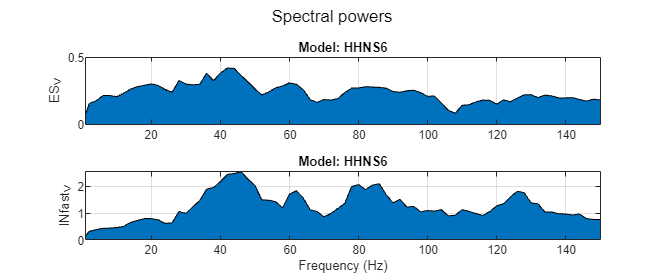

dl.dlPlotAllPotentials('avgfft');

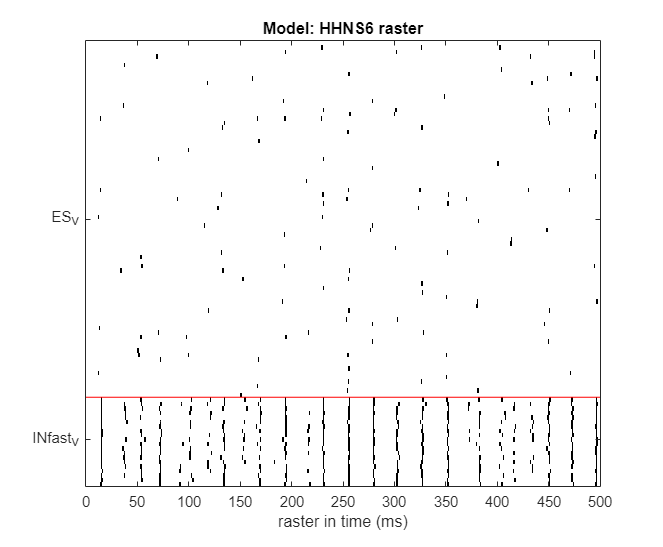

dl.dlPlotAllPotentials('raster');

fprintf("Initial natural frequency ES = %f, INfast = %f\n", dl.dlLastOutputs{1}, dl.dlLastOutputs{2});

Initial natural frequency ES = 44.888798, INfast = 48.969598


dlTrainOptions = containers.Map(); % Train options; MUST be a Map() data structure
dlTrainOptions('dlLambda') = 1e-3; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 10; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.0;

dlTrainOptions('dlExcludeDiverge') = 0; % Exclude non-optimals from model log
dlTrainOptions('dlCheckpointLengthCap') = 11;
dlTrainOptions('dlUpdateVerbose') = 1; % Recommended to be 1 for debugging purposes
dlTrainOptions('dlTrainIncludeList') = ["ES_INfast_iGABAa_tauD", "ES_noise", "INfast_noise"];

dlTrainOptions('dlTrainRestrictList') = ["ES_noise", "INfast_noise"]; % Restrict list
dlTrainOptions('dlTrainRestrictCoef') = {0.02, 0.02}; % Restrict rate coeffs (Variation restriction)
dlTrainOptions('dlTrainRestrictBound') = {[30 50], [30 50]}; % Restrict boundary values (PDE)
dlTrainOptions('dlCheckpointCoefficient') = 1.7;

dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

-> Training started:
-->dlBatchs (batch size) was not determined in options map, default dlBatchs = 1
--->Ignore dlBatchs if your update mode is trial or epoch.

-->Included variable(s) on fitting: 
---> ES_INfast_iGABAa_tauD
---> ES_noise
---> INfast_noise
-->Excluded variable(s) on fitting: 
-->No variables were manually excluded in the fitting exclude list.
--->No dynasim variables are excluded by default.
-->Restricted variable(s) on fitting: 
---> ES_noise
---> INfast_noise
-->Synchronized variable(s) on fitting: 
-->No variables were manually synchronized.
--->No dynasim variables are synchronized by default.
-->Learning rule was not determined in options map
--->Default dlLearningRule = 'GeneralizedStochasticDeltaRule'
-->Update mode was not determined in options map, default dlUpdateMode = 'trial'
-->No custom logs specified; Ignore this if you did not have custom logs.
-->Checkpoint flag was not determined in options map, default dlCheckpoint = 'true'
-->dlUpdateVerbose is 1 (

-->Log flag for loss plot is not specified; default = 1.


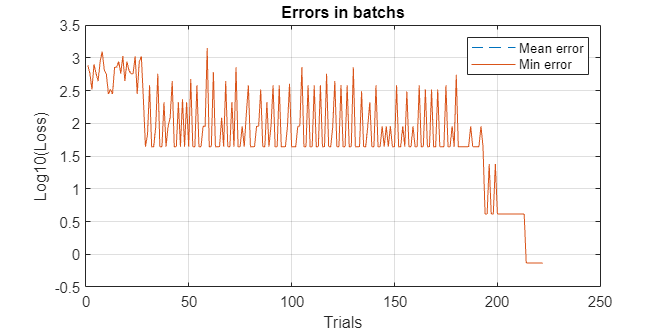

dl.dlPlotBatchErrors(1);

dl.dlLoadOptimal();

		Checkpoint file loaded from dlModels/HHNS6/Optimal 
---->Optimal [Parallel]


dl.dlSimulate();

Done.



--->No limit set or bad format:
---->opts map should have opts("lf") and opts("hf") as real positive values.

--->Default lf/hf = 1.0Hz/150.0HzTemp edit for q subplots; average fft


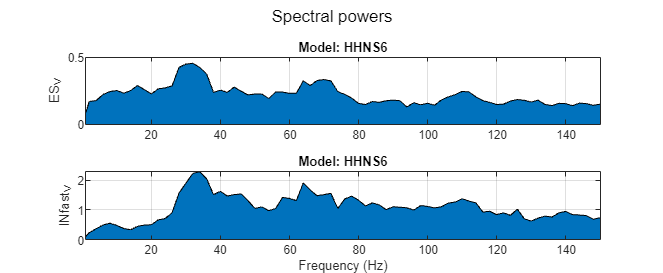

dl.dlPlotAllPotentials('avgfft');

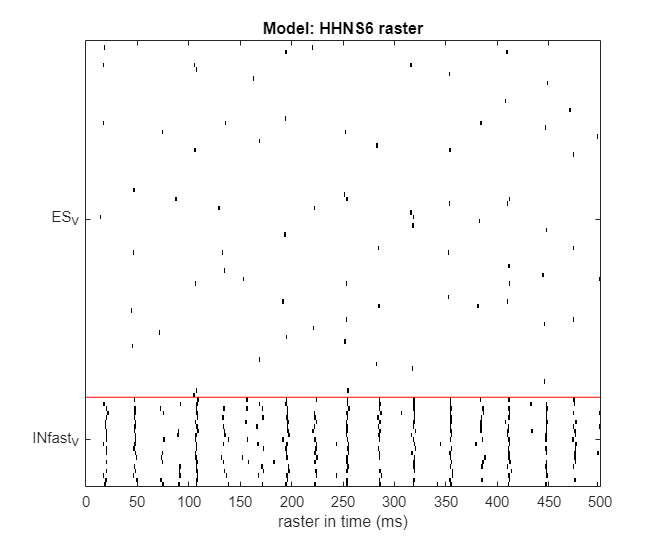

dl.dlPlotAllPotentials('raster');


fprintf("Final natural frequency ES = %f, INfast = %f\n", dl.dlLastOutputs{1}, dl.dlLastOutputs{2});

Final natural frequency ES = 30.605999, INfast = 30.605999


optimal_param_file = fullfile(study_dir, 'Optimalparams.mat');
load(optimal_param_file, 'p');
fprintf('Final TauD(IN): %g, ES_Noise = %g, INF_Noise = %g\n', p.ES_INfast_iGABAa_tauD, p.ES_noise, p.INfast_noise);

Final TauD(IN): 29.9789, ES_Noise = 50, INF_Noise = 41.0086


## 2.4: Band frequency optimization


$$:N \rightarrow f(<R,\omega_{Natural}>; \nabla I_{app}, Noise)$$


RunDuration = 500; % In ms (miliseconds)
study_dir = 'dlModels/HHNS7';

eqns={
  'dV/dt=Iapp+@current+noise*randn(1,N_pop); Iapp=0; noise=0'
};

Iapp = 10;

gGABAfast = .1;
gAMPA = .1;

tauGABAfast = 5;
tauAMPA = 2;

s=[];
s.populations(1).name='ES';
s.populations(1).size=80;
s.populations(1).equations=eqns;
s.populations(1).mechanism_list={'iNa','iK'};
s.populations(1).parameters={'Iapp',Iapp,'gNa',120,'gK',36,'noise', 40};

s.populations(2).name='INfast';
s.populations(2).size=20;
s.populations(2).equations=eqns;
s.populations(2).mechanism_list={'iNa','iK'};
s.populations(2).parameters={'Iapp',0,'gNa',120,'gK',36,'noise', 40};

s.connections(1).direction='INfast->ES';
s.connections(1).mechanism_list={'iGABAa'};
s.connections(1).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast};

s.connections(2).direction='ES->INfast';
s.connections(2).mechanism_list={'iAMPA'};
s.connections(2).parameters={'tauD',tauAMPA,'gAMPA',gAMPA};

s.connections(3).direction='INfast->INfast';
s.connections(3).mechanism_list={'iGABAa'};
s.connections(3).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast};

## Passing to DynaLearn

dl = DynaLearn(s, study_dir, 'mex', 'HHNS7', 1);



@DS.DL
>Creating DynaLearn model object 
->NOTE: Parallel flag is 0 by default.
-->To change parallel flag, set dlParallelFlag = 0 or 1
->Parallel flag is : 1

-->If you encountered an error related to parallel flag, set dlParallelFlag = 0.

PREPARING STUDY:
Creating study directory: D:\Works\Computational\DynaSim\dlModels\HHNS5
Creating data directory: D:\Works\Computational\DynaSim\dlModels\HHNS5\data
Creating results directory: D:\Works\Computational\DynaSim\dlModels\HHNS5\results
saving study file: D:\Works\Computational\DynaSim\dlModels\HHNS5\studyinfo.mat
Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 12 workers.

PREPARING SOLVER:
Creating solver directory D:\Works\Computational\DynaSim\dlModels\HHNS5\solve\sim1
Changing directory to D:\Works\Computational\DynaSim\dlModels\HHNS5\solve\sim1
Saving params.mat
Creating solver file: D:\Works\Computational\DynaSim\dlModels\HHNS5\solve\sim1\solve_ode_20230705103026_852.m
Compiling 


Parallel simulations complete.

--------
--->Constructing graph ... Done.

@DS.DL:DynaLearn model created.


dl.dlSave();


->Model saved in "dlModels/HHNS5/dlFile.mat".


## Load (ONLY IF ALREADY EXISTS)

id = 7; % 1, 2, ...
dl = DynaLearn.dlLoader(char("dlModels/HHNS" + num2str(id)));

DL object loaded from dlModels/HHNS5 
Params.mat file loaded from dlModels/HHNS5 
--------
--->Constructing graph ... Done.

Reinitialized.


param_file = fullfile(study_dir, 'params.mat');
load(param_file, 'p');
fprintf('Initial TauD(IN): %g, ES_Noise = %g, INF_Noise = %g\n', p.ES_INfast_iGABAa_tauD, p.ES_noise, p.INfast_noise);

Initial TauD(IN): 5, ES_Noise = 40, INF_Noise = 40


target_FRQ = 25; % Hz
target_FRQ2 = 40; % Hz

dlInputParameters = {dlNullInputs(RunDuration)}; % Null inputs (no external stimulation).
dlOutputParameters = [{['ES', '_V'], 1:80, [10 RunDuration], 'fnat'}; {['INfast', '_V'], 1:20, [10 RunDuration], 'fnat'}];
dlTargetParameters = {[{'MSE', 1, target_FRQ, 1}; {'MSE', 2, target_FRQ2, 1}]}; % Format: (1)Mode;(2)Output indices;(3)Target value;(4)Weight in loss equation

% Define training options
dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1e-5; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 1; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.4;

dlTrainOptions('dlExcludeDiverge') = 0; % Exclude non-optimals from model log
dlTrainOptions('dlCheckpointLengthCap') = 11;
dlTrainOptions('dlUpdateVerbose') = 1;
dlTrainOptions('dlTrainIncludeList') = ["ES_INfast_iGABAa_tauD", "ES_noise", "INfast_noise"];

dlTrainOptions('dlTrainRestrictList') = ["ES_noise", "INfast_noise"]; % Restrict list
dlTrainOptions('dlTrainRestrictCoef') = {.1, .1}; % Restrict coeffs
dlTrainOptions('dlTrainSyncList') = ["ES_INfast_iGABAa_tauD", ...
    "INfast_INfast_iGABAa_tauD"]; % Each array row will be overrided
                                  % by synchronizing to the first element
dlTrainOptions('dlCheckpointCoefficient') = 1.2;

dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

-> Training started:
-->dlBatchs (batch size) was not determined in options map, default dlBatchs = 1
--->Ignore dlBatchs if your update mode is trial or epoch.

-->Included variable(s) on fitting: 
---> ES_INfast_iGABAa_tauD
---> ES_noise
---> INfast_noise
-->Excluded variable(s) on fitting: 
-->No variables were manually excluded in the fitting exclude list.
--->No dynasim variables are excluded by default.
-->Restricted variable(s) on fitting: 
---> ES_noise
---> INfast_noise
-->Synchronized variable(s) on fitting: 
--->N.1:     "ES_INfast_iGABAa_tauD"    "INfast_INfast_iGABAa_tauD"

---->NOTE: SyncList format should be group(row)Xvariables(column).
---->On each group, All variables will be set to be equal to the first one.

-->Learning rule was not determined in options map
--->Default dlLearningRule = 'GeneralizedStochasticDeltaRule'
-->Update mode was not determined in options map, default dlUpdateMode = 'trial'
-->No custom logs specified; Ignore this if you did not have custom 

dl.dlSimulate();

Done.


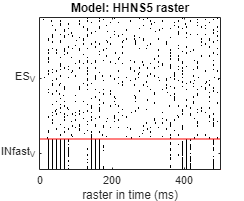

dl.dlPlotAllPotentials('raster');

fprintf("Initial natural frequency ES = %f, INfast = %f\n", dl.dlLastOutputs{1}, dl.dlLastOutputs{2});

Initial natural frequency ES = 124.464395, INfast = 102.019996


dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1e-1; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 100; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.4;

dlTrainOptions('dlExcludeDiverge') = 0; % Exclude non-optimals from model log
dlTrainOptions('dlCheckpointLengthCap') = 11;
dlTrainOptions('dlUpdateVerbose') = 1;
dlTrainOptions('dlTrainIncludeList') = ["ES_INfast_iGABAa_tauD", "ES_noise", "INfast_noise"];

dlTrainOptions('dlTrainRestrictList') = ["ES_noise", "INfast_noise"]; % Restrict list
dlTrainOptions('dlTrainRestrictCoef') = {0.05, 0.05}; % Restrict coeffs
dlTrainOptions('dlTrainSyncList') = ["ES_INfast_iGABAa_tauD", ...
    "INfast_INfast_iGABAa_tauD"]; % Each array row will be overrided
                                  % by synchronizing to the first element

dlTrainOptions('dlCheckpointCoefficient') = 1.2;

dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

-> Training started:
-->dlBatchs (batch size) was not determined in options map, default dlBatchs = 1
--->Ignore dlBatchs if your update mode is trial or epoch.

-->Included variable(s) on fitting: 
---> ES_INfast_iGABAa_tauD
---> ES_noise
---> INfast_noise
-->Excluded variable(s) on fitting: 
-->No variables were manually excluded in the fitting exclude list.
--->No dynasim variables are excluded by default.
-->Restricted variable(s) on fitting: 
---> ES_noise
---> INfast_noise
-->Synchronized variable(s) on fitting: 
--->N.1:     "ES_INfast_iGABAa_tauD"    "INfast_INfast_iGABAa_tauD"

---->NOTE: SyncList format should be group(row)Xvariables(column).
---->On each group, All variables will be set to be equal to the first one.

-->Learning rule was not determined in options map
--->Default dlLearningRule = 'GeneralizedStochasticDeltaRule'
-->Update mode was not determined in options map, default dlUpdateMode = 'trial'
-->No custom logs specified; Ignore this if you did not have custom 

-->Log flag for loss plot is not specified; default = 1.


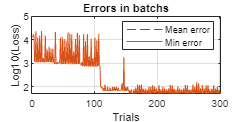


dl.dlPlotBatchErrors(1);

dl.dlLoadOptimal();

		Checkpoint file loaded from dlModels/HHNS5/Optimal 
---->Optimal [Parallel]


dl.dlSimulate();

Done.


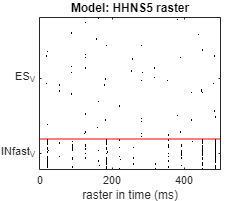

dl.dlPlotAllPotentials('raster');


fprintf("Final natural frequency ES = %f, INfast = %f\n", dl.dlLastOutputs{1}, dl.dlLastOutputs{2});

Final natural frequency ES = 18.363599, INfast = 42.848398


optimal_param_file = fullfile(study_dir, 'Optimalparams.mat');
load(optimal_param_file, 'p');
fprintf('Final TauD(IN): %g, ES_Noise = %g, INF_Noise = %g\n', p.ES_INfast_iGABAa_tauD, p.ES_noise, p.INfast_noise);

Final TauD(IN): 30.7252, ES_Noise = 40.5093, INF_Noise = 40.0105


## 2.5: Band power spectrum ratio optimization


$$:N \rightarrow f(\frac{\beta_{8-30Hz}}{\gamma_{40-90Hz}}; \nabla I_{app}, Noise)$$


RunDuration = 400; % In ms (miliseconds)
study_dir = 'dlModels/HHNS8';

eqns={
  'dV/dt=Icond+Iapp+@current+noise*randn(1,N_pop); Icond=0; Iapp=0; noise=0'
};

Iapp = 5;

gGABAfast = .1;
gAMPA = .1;

tauGABAfast = 5;
tauAMPA = 2;
kIE = ones(20, 80)*0.5;
kEI = ones(80, 20)*0.5;
kII = ones(20, 20)*0.5;

s=[];
s.populations(1).name='ES';
s.populations(1).size=80;
s.populations(1).equations=eqns;
s.populations(1).mechanism_list={'iNa','iK'};
s.populations(1).parameters={'Iapp',Iapp,'gNa',120,'gK',36,'noise', 30};

s.populations(2).name='INfast';
s.populations(2).size=20;
s.populations(2).equations=eqns;
s.populations(2).mechanism_list={'iNa','iK'};
s.populations(2).parameters={'Iapp',0,'gNa',120,'gK',36,'noise', 30};

s.connections(1).direction='INfast->ES';
s.connections(1).mechanism_list={'iGABAa'};
s.connections(1).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast, 'netcon', kIE};

s.connections(2).direction='ES->INfast';
s.connections(2).mechanism_list={'iAMPA'};
s.connections(2).parameters={'tauD',tauAMPA,'gAMPA',gAMPA, 'netcon', kEI};

s.connections(3).direction='INfast->INfast';
s.connections(3).mechanism_list={'iGABAa'};
s.connections(3).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast, 'netcon', kII};

## Passing to DynaLearn

dl = DynaLearn(s, study_dir, 'mex', 'HHNS8', 1);



@DS.DL
>Creating DynaLearn model object 
->NOTE: Parallel flag is 0 by default.
-->To change parallel flag, set dlParallelFlag = 0 or 1
->Parallel flag is : 1

-->If you encountered an error related to parallel flag, set dlParallelFlag = 0.

PREPARING STUDY:
Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 12 workers.

PREPARING SOLVER:
Changing directory to D:\Works\Computational\DynaSim\dlModels\HHNS8\solve\sim1
Saving params.mat
Creating solver file: D:\Works\Computational\DynaSim\dlModels\HHNS8\solve\sim1\solve_ode_20230802145429_833.m
Compiling file: D:\Works\Computational\DynaSim\dlModels\HHNS8\solve\sim1\solve_ode_20230802145429_833.m
            to: D:\Works\Computational\DynaSim\dlModels\HHNS8\solve\sim1\solve_ode_20230802145429_833_mex
Code generation successful.

    MEX generation complete! 
    Elapsed time: 15.0 seconds. 
    Removing temporary codemex directory: D:\Works\Computational\DynaSim\dlModels\HHNS8\solve\sim1\c


Parallel simulations complete.

--------
--->Constructing graph ... Done.

@DS.DL:DynaLearn model created.


dl.dlSave();


->Model saved in "dlModels/HHNS8/dlFile.mat".


## Load (ONLY IF ALREADY EXISTS)

id = 8; % 1, 2, ...
dl = DynaLearn.dlLoader(char("dlModels/HHNS" + num2str(id)));

DL object loaded from dlModels/HHNS8 
Params.mat file loaded from dlModels/HHNS8 
--------
--->Constructing graph ... Done.

Reinitialized.


param_file = fullfile(study_dir, 'params.mat');
load(param_file, 'p');
fprintf('Initial TauD(IN): %g, ES_Noise = %g, INF_Noise = %g, avg.IEconn = %g\n', p.ES_INfast_iGABAa_tauD, p.ES_noise, p.INfast_noise, mean(mean(p.INfast_ES_iAMPA_netcon)));

Initial TauD(IN): 5, ES_Noise = 30, INF_Noise = 30, avg.IEconn = 0.5


trialParams1 = containers.Map();
trialParams2 = containers.Map();

trialParams1('tspan') = [0 400];
trialParams2('tspan') = [0 400];
trialParams1('ES_Icond') = 10;
trialParams2('ES_Icond') = 0;

dlInputParameters = {trialParams1; trialParams2}; % Two inputs (Icond=0?10).
dlOutputParameters = [{['ES', '_V'], 1:80, [10 RunDuration], 'afr'}; {['ES', '_V'], 1:80, [10 RunDuration], 'av'}; {['INfast', '_V'], 1:20, [10 RunDuration], 'av'}];
dlTargetParameters = {{{'QRPenalty', 3, 3.2, 10., 10, 40, 40, 70}; {'MSE', 2, -60, .1}; {'MSE', 3, -55, .1}}; ...
    {{'QRPenalty', 1, 4.0, 10., 10, 40, 40, 70}; {'MSE', 2, -60, .1}; {'MSE', 3, -55, .1}}}; % Format: (1)Mode;(2)Output indices;(3)Target value;(4)Weight in loss equation

% Define training options
dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1e-5; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 2; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.4;

dlTrainOptions('dlExcludeDiverge') = 0; % Exclude non-optimals from model log
dlTrainOptions('dlCheckpointLengthCap') = 11;
dlTrainOptions('dlUpdateVerbose') = 1;
dlTrainOptions('dlTrainIncludeList') = ["ES_noise", "INfast_noise"];

dlTrainOptions('dlUpdateMode') = 'batch';
dlTrainOptions('dlTrainRestrictList') = ["ES_noise", "INfast_noise"]; % Restrict list
dlTrainOptions('dlTrainRestrictCoef') = {.1, .1}; % Restrict coeffs
dlTrainOptions('dlTrainSyncList') = ["ES_INfast_iGABAa_tauD", ...
    "INfast_INfast_iGABAa_tauD"]; % Each array row will be overrided
                                  % by synchronizing to the first element

dlTrainOptions('dlBatchs') = 2;
dlTrainOptions('dlCheckpointCoefficient') = 1.2;

dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

-> Training started:

-->Included variable(s) on fitting: 
---> ES_noise
---> INfast_noise
-->Excluded variable(s) on fitting: 
-->No variables were manually excluded in the fitting exclude list.
--->No dynasim variables are excluded by default.
-->Restricted variable(s) on fitting: 
---> ES_noise
---> INfast_noise
-->Synchronized variable(s) on fitting: 
--->N.1:     "ES_INfast_iGABAa_tauD"    "INfast_INfast_iGABAa_tauD"

---->NOTE: SyncList format should be group(row)Xvariables(column).
---->On each group, All variables will be set to be equal to the first one.

-->Learning rule was not determined in options map
--->Default dlLearningRule = 'GeneralizedStochasticDeltaRule'
-->No custom logs specified; Ignore this if you did not have custom logs.
-->Checkpoint flag was not determined in options map, default dlCheckpoint = 'true'
-->dlUpdateVerbose is 1 (On)
-->Adaptive lambda is active. Lambda (learning rate) will be changed based on volatility of model error.
--->Reminder: you have c

dl.dlSimulate();

Done.



--->No limit set or bad format:
---->opts map should have opts("lf") and opts("hf") as real positive values.

--->Default lf/hf = 1.0Hz/150.0HzTemp edit for q subplots; average fft


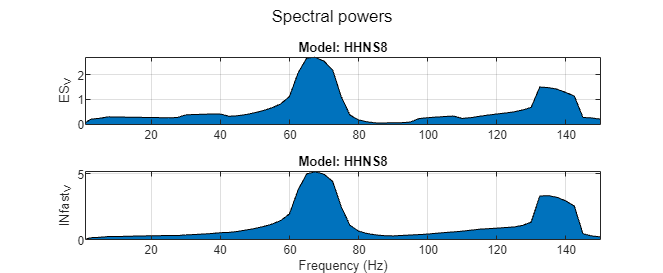

dl.dlPlotAllPotentials('avgfft');

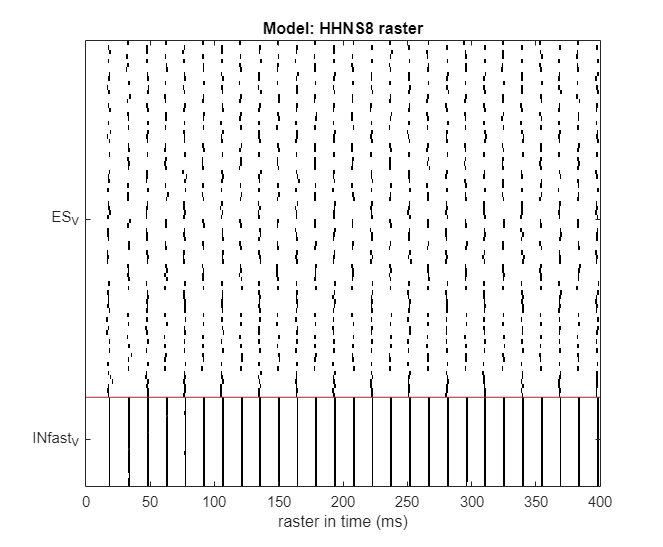

dl.dlPlotAllPotentials('raster');

fprintf("Initial aFR: %f, AV: ES = %f, INfast = %f\n", dl.dlLastOutputs{1}, dl.dlLastOutputs{2}, dl.dlLastOutputs{3});

Initial aFR: 34.734683, AV: ES = -63.793705, INfast = -59.842604


% Define training options
dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1e-3; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 10; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.0;

dlTrainOptions('dlExcludeDiverge') = 0; % Exclude non-optimals from model log
dlTrainOptions('dlCheckpointLengthCap') = 11;
dlTrainOptions('dlUpdateVerbose') = 1;
dlTrainOptions('dlTrainIncludeList') = ["ES_noise", "INfast_noise", "INfast_ES_iAMPA_netcon"];

dlTrainOptions('dlUpdateMode') = 'batch';
dlTrainOptions('dlTrainRestrictList') = ["ES_noise", "INfast_noise"]; % Restrict list
dlTrainOptions('dlTrainRestrictCoef') = {.1, .1}; % Restrict coeffs
dlTrainOptions('dlTrainRestrictBound') = {[20 40], [20 40]}; % Restrict boundary values (PDE)

dlTrainOptions('dlBatchs') = 2;
dlTrainOptions('dlTrainSyncList') = ["ES_INfast_iGABAa_tauD", ...
    "INfast_INfast_iGABAa_tauD"]; % Each array row will be overrided
                                  % by synchronizing to the first element

dlTrainOptions('dlCheckpointCoefficient') = 1.1;

dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

-> Training started:

-->Included variable(s) on fitting: 
---> ES_noise
---> INfast_noise
---> INfast_ES_iAMPA_netcon
-->Excluded variable(s) on fitting: 
-->No variables were manually excluded in the fitting exclude list.
--->No dynasim variables are excluded by default.
-->Restricted variable(s) on fitting: 
---> ES_noise
---> INfast_noise
-->Synchronized variable(s) on fitting: 
--->N.1:     "ES_INfast_iGABAa_tauD"    "INfast_INfast_iGABAa_tauD"

---->NOTE: SyncList format should be group(row)Xvariables(column).
---->On each group, All variables will be set to be equal to the first one.

-->Learning rule was not determined in options map
--->Default dlLearningRule = 'GeneralizedStochasticDeltaRule'
-->No custom logs specified; Ignore this if you did not have custom logs.
-->Checkpoint flag was not determined in options map, default dlCheckpoint = 'true'
-->dlUpdateVerbose is 1 (On)
-->Adaptive lambda is active. Lambda (learning rate) will be changed based on volatility of model err

-->Log flag for loss plot is not specified; default = 1.


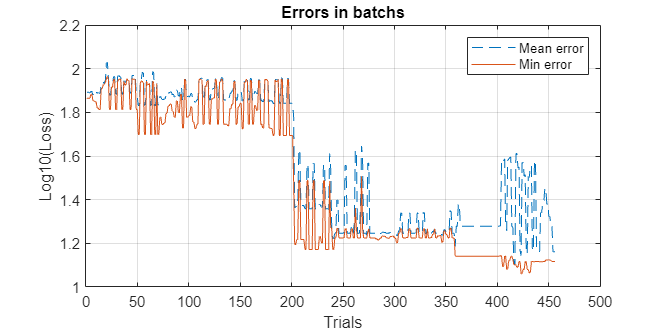

dl.dlPlotBatchErrors(2);

dl.dlLoadOptimal();

		Checkpoint file loaded from dlModels/HHNS8/Optimal 
---->Optimal [Parallel]


dl.dlSimulate();

Done.


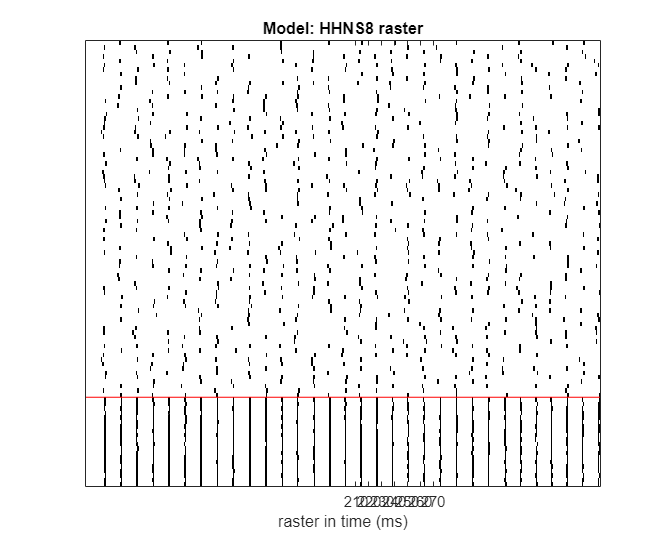

dl.dlPlotAllPotentials('avgfft');
dl.dlPlotAllPotentials('raster');

fprintf("Final aFR: %f, AV: ES = %f, INfast = %f\n", dl.dlLastOutputs{1}, dl.dlLastOutputs{2}, dl.dlLastOutputs{3});

Final aFR: 28.197898, AV: ES = -65.381496, INfast = -57.087780


optimal_param_file = fullfile(study_dir, 'Optimalparams.mat');
load(optimal_param_file, 'p');
fprintf('Final TauD(IN): %g, ES_Noise = %g, IN_Noise = %g, avg.IEconn = %g\n', p.ES_INfast_iGABAa_tauD, p.ES_noise, p.INfast_noise, mean(mean(p.INfast_ES_iAMPA_netcon)));

Final TauD(IN): 5, ES_Noise = 29.9626, IN_Noise = 29.9677, avg.IEconn = 0.623757


## 3.1: Single stimulus response optimization


$$:N?C_{p} \rightarrow f( [N] \frac{\beta_{8-30Hz}}{\gamma_{40-90Hz}} < [C_{P}] \frac{\beta_{8-30Hz}}{\gamma_{40-90Hz}}; \nabla I_{app}, Tau_D, Noise)$$


RunDuration = 500; % In ms (miliseconds)
study_dir = 'dlModels/HHNS10'; 

eqns={
  'dV/dt=Icond+Iapp+@current+noise*randn(1,N_pop); Icond=0; Iapp=0; noise=0'
};

Iapp = 0;

gGABAfast = .1;
gAMPA = .1;

tauGABAfast = 15;
tauAMPA = 10;

kIE = ones(20, 80)*0.5;
kEI = ones(80, 20)*0.5;
kII = ones(20, 20)*0.5;

s=[];
s.populations(1).name='ES';
s.populations(1).size=80;
s.populations(1).equations=eqns;
s.populations(1).mechanism_list={'iNa','iK'};
s.populations(1).parameters={'Iapp',Iapp,'gNa',120,'gK',36,'noise', 30};

s.populations(2).name='INfast';
s.populations(2).size=20;
s.populations(2).equations=eqns;
s.populations(2).mechanism_list={'iNa','iK'};
s.populations(2).parameters={'Iapp',0,'gNa',120,'gK',36,'noise', 30};

s.connections(1).direction='INfast->ES';
s.connections(1).mechanism_list={'iGABAa'};
s.connections(1).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast, 'netcon', kIE};

s.connections(2).direction='ES->INfast';
s.connections(2).mechanism_list={'iAMPA'};
s.connections(2).parameters={'tauD',tauAMPA,'gAMPA',gAMPA, 'netcon', kEI};

s.connections(3).direction='INfast->INfast';
s.connections(3).mechanism_list={'iGABAa'};
s.connections(3).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast, 'netcon', kII};

## Passing to DynaLearn

dl = DynaLearn(s, study_dir, 'mex', 'HHNS10', 1); 



@DS.DL
>Creating DynaLearn model object 
->NOTE: Parallel flag is 0 by default.
-->To change parallel flag, set dlParallelFlag = 0 or 1
->Parallel flag is : 1

-->If you encountered an error related to parallel flag, set dlParallelFlag = 0.

PREPARING STUDY:
Creating study directory: D:\Works\Computational\DynaSim\dlModels\HHNS10
Creating data directory: D:\Works\Computational\DynaSim\dlModels\HHNS10\data
Creating results directory: D:\Works\Computational\DynaSim\dlModels\HHNS10\results
saving study file: D:\Works\Computational\DynaSim\dlModels\HHNS10\studyinfo.mat
Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 12 workers.

PREPARING SOLVER:
Creating solver directory D:\Works\Computational\DynaSim\dlModels\HHNS10\solve\sim1
Changing directory to D:\Works\Computational\DynaSim\dlModels\HHNS10\solve\sim1
Saving params.mat
Creating solver file: D:\Works\Computational\DynaSim\dlModels\HHNS10\solve\sim1\solve_ode_20230804174640_542.m
Com


Parallel simulations complete.

--------
--->Constructing graph ... Done.

@DS.DL:DynaLearn model created.


dl.dlSave();


->Model saved in "dlModels/HHNS10/dlFile.mat".


## Load (ONLY IF ALREADY EXISTS)

id = 10; % 1, 2, ...
dl = DynaLearn.dlLoader(char("dlModels/HHNS" + num2str(id)));

DL object loaded from dlModels/HHNS10 
Params.mat file loaded from dlModels/HHNS10 
--------
--->Constructing graph ... Done.

Reinitialized.


param_file = fullfile(study_dir, 'params.mat');
load(param_file, 'p');
fprintf('Initial TauD(IN): %g, ES_Noise = %g, INF_Noise = %g, avg.IEconn = %g\n', p.ES_INfast_iGABAa_tauD, p.ES_noise, p.INfast_noise, mean(mean(p.INfast_ES_iAMPA_netcon)));

Initial TauD(IN): 15, ES_Noise = 30, INF_Noise = 30, avg.IEconn = 0.5


trialParams1 = containers.Map();
trialParams2 = containers.Map();
trialParams3 = containers.Map();

trialParams1('tspan') = [0 RunDuration];
trialParams2('tspan') = [0 RunDuration];
trialParams3('tspan') = [0 RunDuration];

trialParams1('ES_Icond') = 1;
trialParams2('ES_Icond') = 2;
trialParams3('ES_Icond') = 3;

freqPenalty = 1000.0;
dlInputParameters = {trialParams1; trialParams2; trialParams3}; % Two inputs (Icond=0?10).
dlOutputParameters = [{['ES', '_V'], 1:80, [10 RunDuration], 'afr'}; {['ES', '_V'], 1:80, [10 RunDuration], 'av'}; {['INfast', '_V'], 1:20, [10 RunDuration], 'av'}];
dlTargetParameters = {{{'QRPenalty', "ES_V", 1.6, freqPenalty, 10, 40, 40, 100}; {'MSE', 2, -65, .01}; {'MSE', 3, -65, .01}}; ...
    {{'QRPenalty', "ES_V", 1.4, freqPenalty, 10, 40, 40, 100}; {'MSE', 2, -65, .01}; {'MSE', 3, -65, .01}}; ...
    {{'QRPenalty', "ES_V", 1.2, freqPenalty, 10, 40, 40, 100}; {'MSE', 2, -65, .01}; {'MSE', 3, -65, .01}}}; % Format: (1)Mode;(2)Output indices;(3)Target value;(4)Weight in loss equation

dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1e-7; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 1; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.0;

dlTrainOptions('dlExcludeDiverge') = 0; % Exclude non-optimals from model log
dlTrainOptions('dlCheckpointLengthCap') = 11;
dlTrainOptions('dlUpdateVerbose') = 1;
dlTrainOptions('dlTrainIncludeList') = ["ES_noise", "INfast_noise", "INfast_ES_iAMPA_netcon"];

dlTrainOptions('dlUpdateMode') = 'batch';
dlTrainOptions('dlTrainRestrictList') = ["ES_noise", "INfast_noise"]; % Restrict list
dlTrainOptions('dlTrainRestrictCoef') = {.1, .1}; % Restrict coeffs
dlTrainOptions('dlTrainRestrictBound') = {[5 50], [5 50]}; % Restrict boundary values (PDE)

dlTrainOptions('dlBatchs') = 3;
dlTrainOptions('dlTrainSyncList') = ["ES_INfast_iGABAa_tauD", ...
    "INfast_INfast_iGABAa_tauD"]; % Each array row will be overrided
                                  % by synchronizing to the first element

dlTrainOptions('dlCheckpointCoefficient') = 1.1;

dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

-> Training started:

-->Included variable(s) on fitting: 
---> ES_noise
---> INfast_noise
---> INfast_ES_iAMPA_netcon
-->Excluded variable(s) on fitting: 
-->No variables were manually excluded in the fitting exclude list.
--->No dynasim variables are excluded by default.
-->Restricted variable(s) on fitting: 
---> ES_noise
---> INfast_noise
-->Synchronized variable(s) on fitting: 
--->N.1:     "ES_INfast_iGABAa_tauD"    "INfast_INfast_iGABAa_tauD"

---->NOTE: SyncList format should be group(row)Xvariables(column).
---->On each group, All variables will be set to be equal to the first one.

-->Learning rule was not determined in options map
--->Default dlLearningRule = 'GeneralizedStochasticDeltaRule'
-->No custom logs specified; Ignore this if you did not have custom logs.
-->Checkpoint flag was not determined in options map, default dlCheckpoint = 'true'
-->dlUpdateVerbose is 1 (On)
-->Adaptive lambda is active. Lambda (learning rate) will be changed based on volatility of model err

Condition1



	->Single trial running: 
Updating parameters of dlModels/HHNS10/solve > 
Done.

	-->Simulation outputs:     {[0.2295]}    {[-73.1321]}    {[-74.7323]}




--->No limit set or bad format:
---->opts map should have opts("lf") and opts("hf") as real positive values.

--->Default lf/hf = 1.0Hz/150.0HzTemp edit for q subplots; average fft


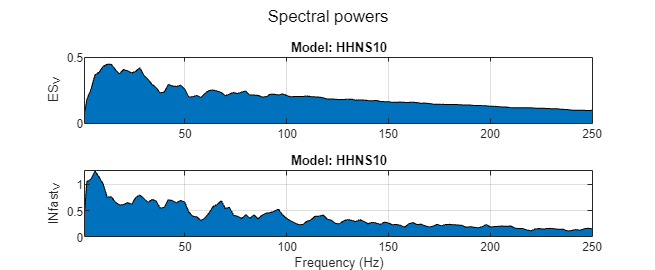

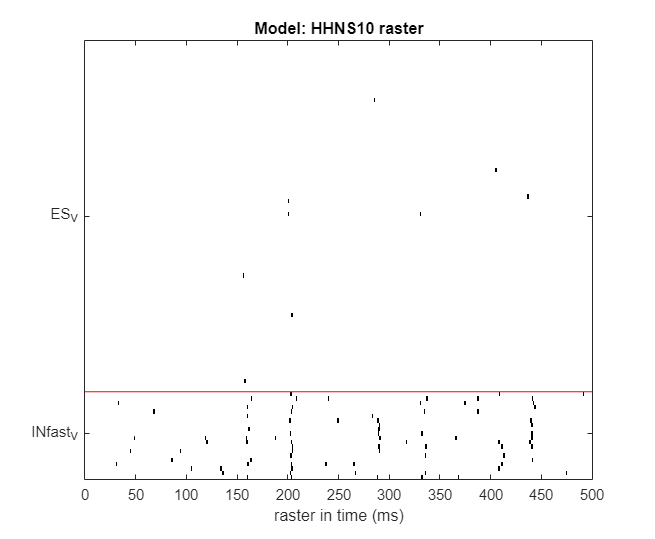

Condition2



	->Single trial running: 
Updating parameters of dlModels/HHNS10/solve > 
Done.

	-->Simulation outputs:     {[1.0967]}    {[-71.9673]}    {[-69.2567]}




--->No limit set or bad format:
---->opts map should have opts("lf") and opts("hf") as real positive values.

--->Default lf/hf = 1.0Hz/150.0HzTemp edit for q subplots; average fft


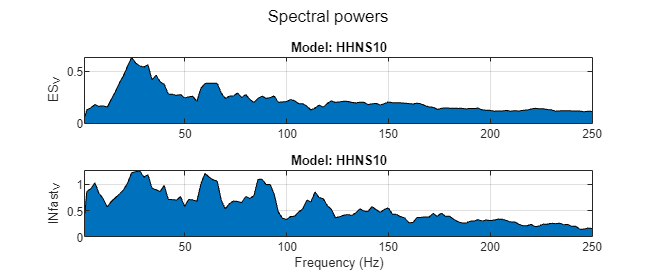

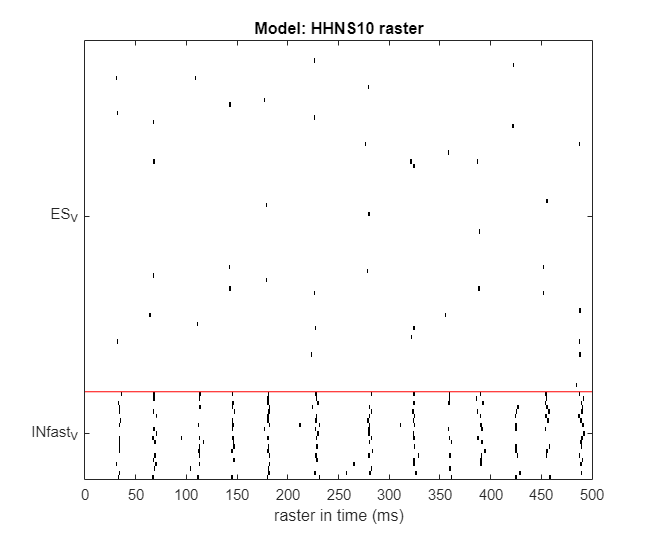

Condition3



	->Single trial running: 
Updating parameters of dlModels/HHNS10/solve > 
Done.

	-->Simulation outputs:     {[2.0404]}    {[-70.9513]}    {[-66.3243]}




--->No limit set or bad format:
---->opts map should have opts("lf") and opts("hf") as real positive values.

--->Default lf/hf = 1.0Hz/150.0HzTemp edit for q subplots; average fft


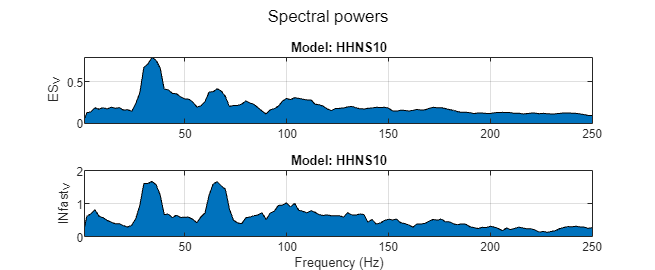

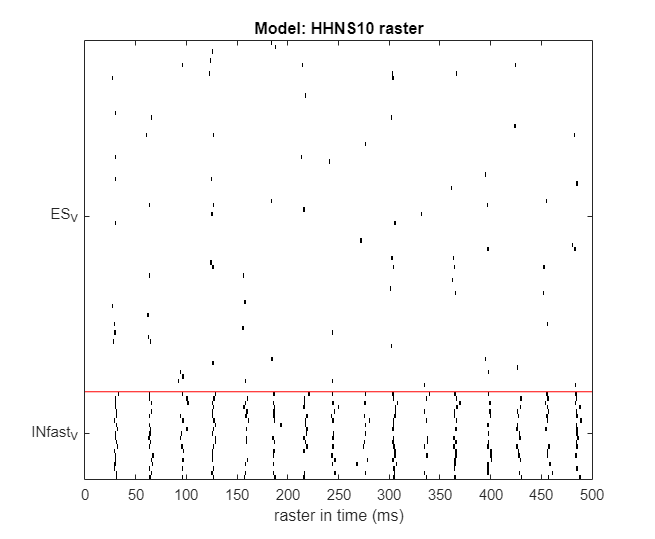

for i = 1:max(size(dlInputParameters, 1))

    disp("Condition" + num2str(i));
    dl.dlRunSimulation(dlInputParameters{i}, dlOutputParameters);
    dl.dlPlotAllPotentials('avgfft');
    dl.dlPlotAllPotentials('raster');

end

dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1e-4; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 10; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.0;

dlTrainOptions('dlExcludeDiverge') = 0; % Exclude non-optimals from model log
dlTrainOptions('dlCheckpointLengthCap') = 31;
dlTrainOptions('dlUpdateVerbose') = 1;
dlTrainOptions('dlTrainIncludeList') = ["ES_noise", "INfast_noise", "INfast_ES_iAMPA_netcon"];

dlTrainOptions('dlTrainRestrictList') = ["ES_noise", "INfast_noise"]; % Restrict list
dlTrainOptions('dlTrainRestrictCoef') = {.1, .1}; % Restrict coeffs
dlTrainOptions('dlTrainRestrictBound') = {[5 40], [5 40]}; % Restrict boundary values (PDE)

dlTrainOptions('dlBatchs') = 3;
dlTrainOptions('dlUpdateMode') = 'batch';

dlTrainOptions('dlCheckpointCoefficient') = 1.2;

dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

-> Training started:

-->Included variable(s) on fitting: 
---> ES_noise
---> INfast_noise
---> INfast_ES_iAMPA_netcon
-->Excluded variable(s) on fitting: 
-->No variables were manually excluded in the fitting exclude list.
--->No dynasim variables are excluded by default.
-->Restricted variable(s) on fitting: 
---> ES_noise
---> INfast_noise
-->Synchronized variable(s) on fitting: 
-->No variables were manually synchronized.
--->No dynasim variables are synchronized by default.
-->Learning rule was not determined in options map
--->Default dlLearningRule = 'GeneralizedStochasticDeltaRule'
-->No custom logs specified; Ignore this if you did not have custom logs.
-->Checkpoint flag was not determined in options map, default dlCheckpoint = 'true'
-->dlUpdateVerbose is 1 (On)
-->Adaptive lambda is active. Lambda (learning rate) will be changed based on volatility of model error.
--->Reminder: you have choosen adaptive lambda but forgot to determine a lambda cap. default dlLambdaCap = 1.00

-->Log flag for loss plot is not specified; default = 1.


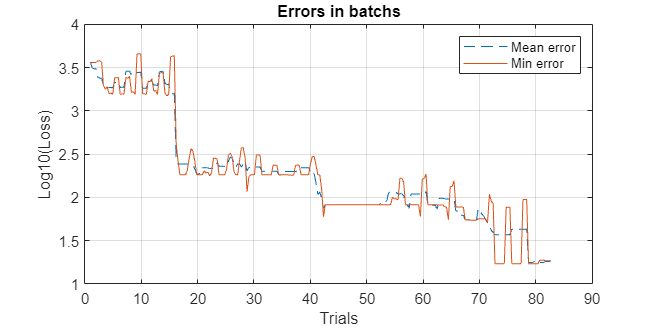

dl.dlPlotBatchErrors(3);

dl.dlLoadOptimal();

		Checkpoint file loaded from dlModels/HHNS10/Optimal 
---->Optimal [Parallel]


Condition1



	->Single trial running: 
Updating parameters of dlModels/HHNS10/solve > 
Done.

	-->Simulation outputs:     {[0.2295]}    {[-73.1320]}    {[-74.7351]}




--->No limit set or bad format:
---->opts map should have opts("lf") and opts("hf") as real positive values.

--->Default lf/hf = 1.0Hz/150.0HzTemp edit for q subplots; average fft


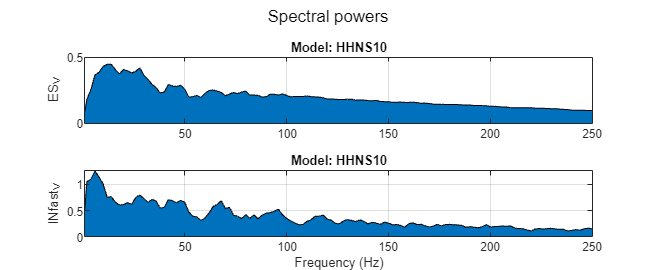

Condition2



	->Single trial running: 
Updating parameters of dlModels/HHNS10/solve > 
Done.

	-->Simulation outputs:     {[1.1222]}    {[-71.9470]}    {[-69.1222]}




--->No limit set or bad format:
---->opts map should have opts("lf") and opts("hf") as real positive values.

--->Default lf/hf = 1.0Hz/150.0HzTemp edit for q subplots; average fft


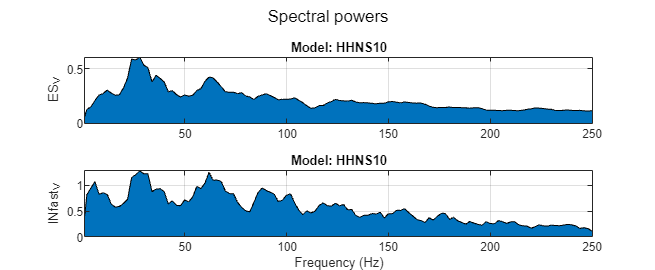

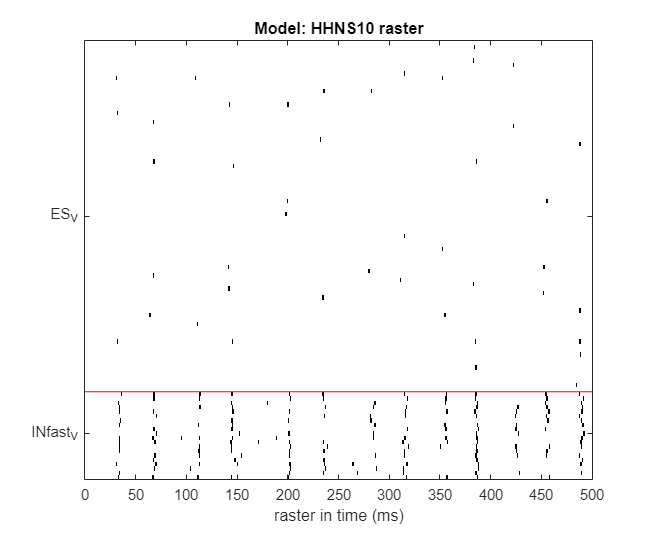

Condition3



	->Single trial running: 
Updating parameters of dlModels/HHNS10/solve > 
Done.

	-->Simulation outputs:     {[2.0659]}    {[-70.9703]}    {[-66.1910]}




--->No limit set or bad format:
---->opts map should have opts("lf") and opts("hf") as real positive values.

--->Default lf/hf = 1.0Hz/150.0HzTemp edit for q subplots; average fft


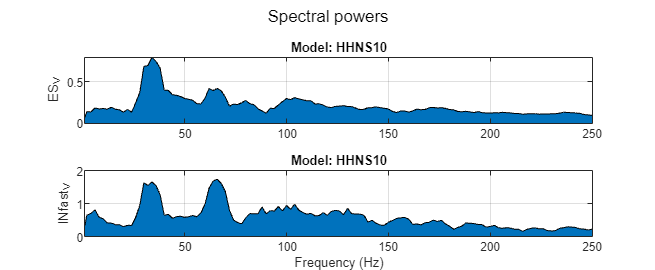

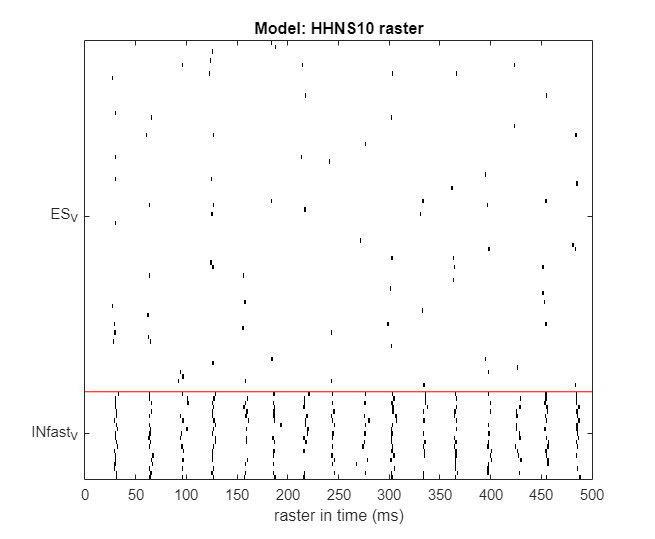

for i = 1:max(size(dlInputParameters, 1))

    disp("Condition" + num2str(i));
    dl.dlRunSimulation(dlInputParameters{i}, dlOutputParameters);
    dl.dlPlotAllPotentials('avgfft');
    dl.dlPlotAllPotentials('raster');

end

fprintf("Final aFR: %f, AV: ES = %f, INfast = %f\n", dl.dlLastOutputs{1}, dl.dlLastOutputs{2}, dl.dlLastOutputs{3});

Final aFR: 2.065905, AV: ES = -70.970310, INfast = -66.191025


optimal_param_file = fullfile(study_dir, 'Optimalparams.mat');
load(optimal_param_file, 'p');
fprintf('Final TauD(IN): %g, ES_Noise = %g, INF_Noise = %g\n', p.ES_INfast_iGABAa_tauD, p.ES_noise, p.INfast_noise);

Final TauD(IN): 15, ES_Noise = 13.9029, INF_Noise = 31.1191


## 3.2: Multiple stimulus response optimization


$$:N?C_{p}?C_{U} \rightarrow f( [C_{U}] \frac{\beta_{8-30Hz}}{\gamma_{40-90Hz}} <  [N] \frac{\beta_{8-30Hz}}{\gamma_{40-90Hz}} <  [C_{P}] \frac{\beta_{8-30Hz}}{\gamma_{40-90Hz}}; \nabla I_{app}, Tau_D, Noise)$$


RunDuration = 500; % In ms (miliseconds)
study_dir = 'dlModels/HHNS11';

eqns={
  'dV/dt=IappCue+wContext.*Context+@current+noise*randn(1,N_pop); Context=1; IappCue=0; wContext=0; noise=0'
};

IappCue = 10;
wContext = 10;

gGABAslow = .1;
gGABAfast = .1;
gAMPA = .1;

tauGABAslow = 20;
tauGABAfast = 5;
tauAMPA = 2;

s=[];
s.populations(1).name='ES';
s.populations(1).size=80;
s.populations(1).equations=eqns;
s.populations(1).mechanism_list={'iNa','iK'};
s.populations(1).parameters={'IappCue',IappCue,'gNa',120,'gK',36,'noise',40};
s.populations(2).name='INfast';
s.populations(2).size=20;
s.populations(2).equations=eqns;
s.populations(2).mechanism_list={'iNa','iK'};
s.populations(2).parameters={'IappCue',IappCue,'gNa',120,'gK',36,'noise',40};
s.populations(3).name='INslow';
s.populations(3).size=20;
s.populations(3).equations=eqns;
s.populations(3).mechanism_list={'iNa','iK'};
s.populations(3).parameters={'IappCue',0,'gNa',120,'gK',36,'noise',40};
s.connections(1).direction='INfast->ES';
s.connections(1).mechanism_list={'iGABAa'};
s.connections(1).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast};
s.connections(2).direction='ES->INfast';
s.connections(2).mechanism_list={'iAMPA'};
s.connections(2).parameters={'tauD',tauAMPA,'gAMPA',gAMPA};
s.connections(3).direction='INslow->ES';
s.connections(3).mechanism_list={'iGABAa'};
s.connections(3).parameters={'tauD',tauGABAslow,'gGABAa',gGABAslow};
s.connections(4).direction='ES->INslow';
s.connections(4).mechanism_list={'iAMPA'};
s.connections(4).parameters={'tauD',tauAMPA,'gAMPA',gAMPA};
s.connections(5).direction='INslow->INfast';
s.connections(5).mechanism_list={'iGABAa'};
s.connections(5).parameters={'tauD',tauGABAslow,'gGABAa',gGABAslow};
s.connections(6).direction='INslow->INslow';
s.connections(6).mechanism_list={'iGABAa'};
s.connections(6).parameters={'tauD',tauGABAslow,'gGABAa',gGABAslow};
s.connections(7).direction='INfast->INslow';
s.connections(7).mechanism_list={'iGABAa'};
s.connections(7).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast};
s.connections(8).direction='INfast->INfast';
s.connections(8).mechanism_list={'iGABAa'};
s.connections(8).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast};

vary = {'INfast','IappCue',[0 IappCue]; 'INslow','wContext',[0 wContext/2 wContext]};

data = dsSimulate(s, 'tspan', [0 1000], 'downsample_factor', 10, ...
                     'solver', 'euler', 'dt', .002, ...
                     'compile_flag', 0, 'parallel_flag', 1, ...
                     'vary', vary, 'verbose_flag', 1);


PREPARING STUDY:
Creating study directory: D:\Works\Computational\DynaSim\study_20230804191239
Creating data directory: D:\Works\Computational\DynaSim\study_20230804191239\data
Creating results directory: D:\Works\Computational\DynaSim\study_20230804191239\results
saving study file: D:\Works\Computational\DynaSim\study_20230804191239\studyinfo.mat
Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 12 workers.

PREPARING SOLVER:

PREPARING SOLVER:
Creating solver directory D:\Works\Computational\DynaSim\study_20230804191239\solve\sim6
Changing directory to D:\Works\Computational\DynaSim\study_20230804191239\solve\sim6
Saving params.mat

PREPARING SOLVER:

PREPARING SOLVER:

PREPARING SOLVER:

PREPARING SOLVER:
Creating solver directory D:\Works\Computational\DynaSim\study_20230804191239\solve\sim5
Changing directory to D:\Works\Computational\DynaSim\study_20230804191239\solve\sim5
Saving params.mat
Creating solver directory D:\Works\Compu


Parallel simulations complete.



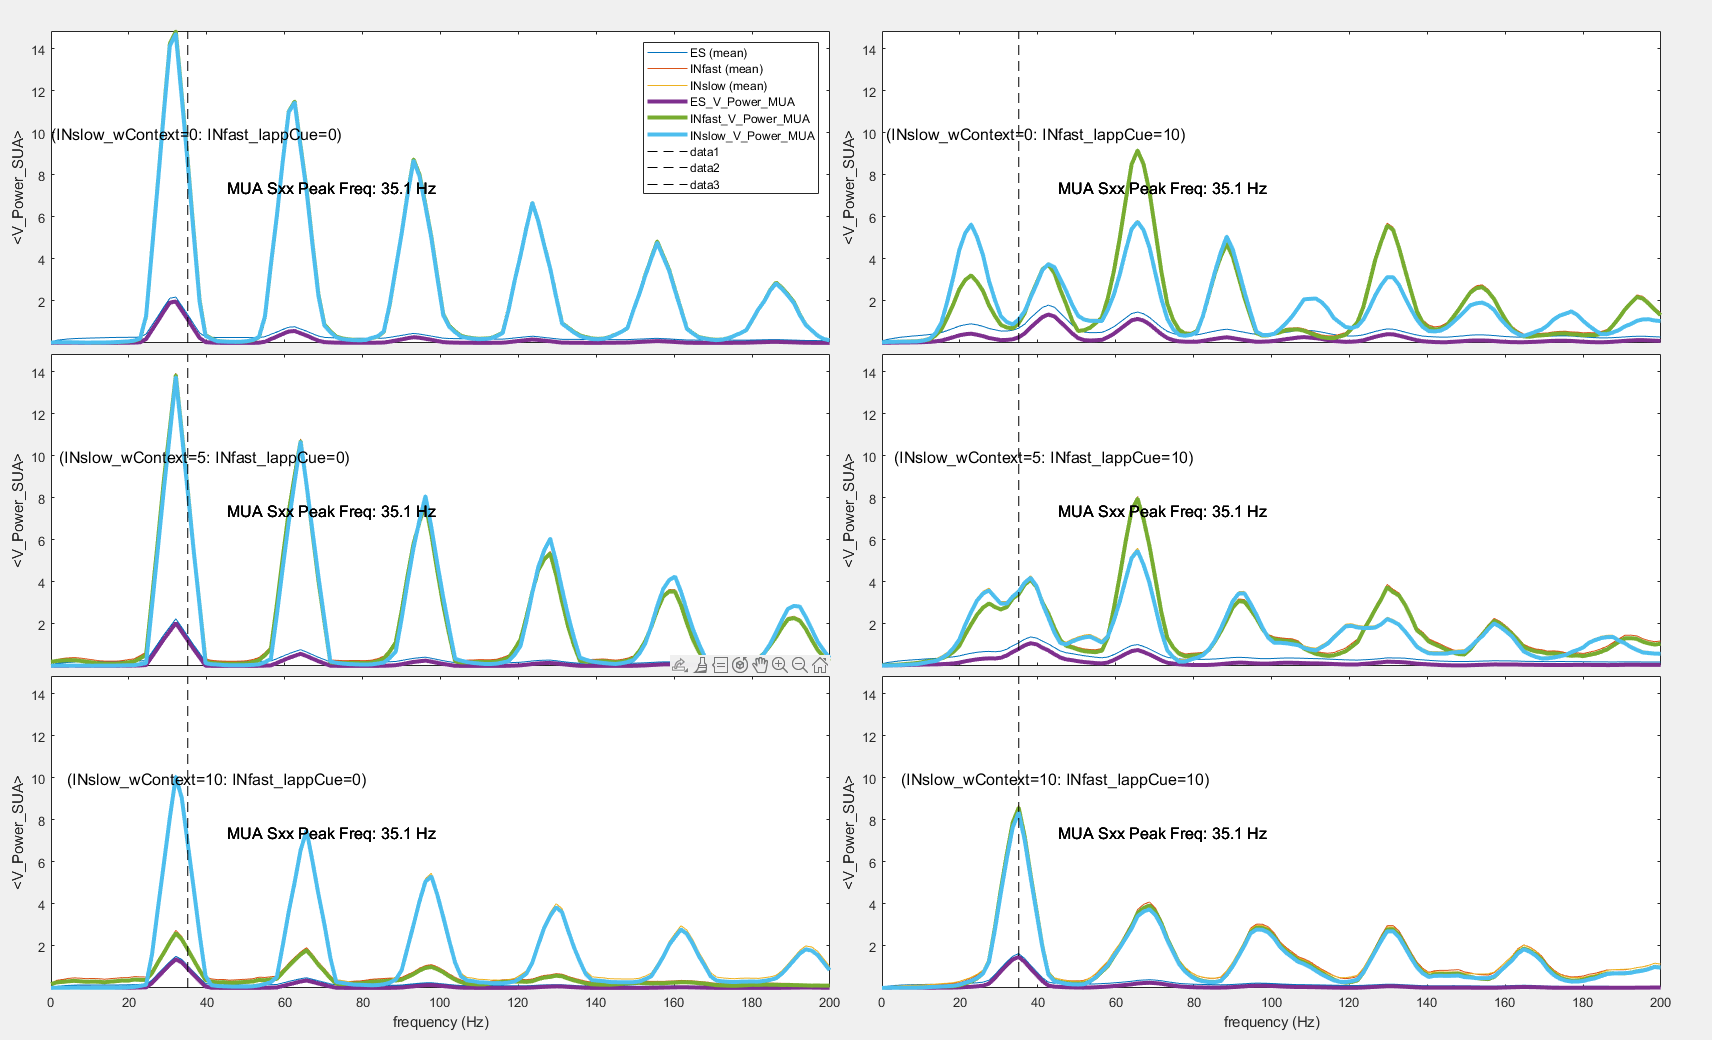

dsPlot(data);
dsPlot(data, 'plot_type','raster');
dsPlot(data, 'plot_type','power');

## Passing to DynaLearn

dl = DynaLearn(s, study_dir, 'mex', 'HHNS11', 1);



@DS.DL
>Creating DynaLearn model object 
->NOTE: Parallel flag is 0 by default.
-->To change parallel flag, set dlParallelFlag = 0 or 1
->Parallel flag is : 1

-->If you encountered an error related to parallel flag, set dlParallelFlag = 0.

PREPARING STUDY:
Creating study directory: D:\Works\Computational\DynaSim\dlModels\HHNS11
Creating data directory: D:\Works\Computational\DynaSim\dlModels\HHNS11\data
Creating results directory: D:\Works\Computational\DynaSim\dlModels\HHNS11\results
saving study file: D:\Works\Computational\DynaSim\dlModels\HHNS11\studyinfo.mat

PREPARING SOLVER:
Creating solver directory D:\Works\Computational\DynaSim\dlModels\HHNS11\solve\sim1
Changing directory to D:\Works\Computational\DynaSim\dlModels\HHNS11\solve\sim1
Saving params.mat
Creating solver file: D:\Works\Computational\DynaSim\dlModels\HHNS11\solve\sim1\solve_ode_20230804191642_493.m
Compiling file: D:\Works\Computational\DynaSim\dlModels\HHNS11\solve\sim1\solve_ode_20230804191642_493.m
         


Parallel simulations complete.

--------
--->Constructing graph ... Done.

@DS.DL:DynaLearn model created.


dl.dlSave();


->Model saved in "dlModels/HHNS11/dlFile.mat".


## Load (ONLY IF ALREADY EXISTS)

id = 11; % 1, 2, ...
dl = DynaLearn.dlLoader(char("dlModels/HHNS" + num2str(id)));

DL object loaded from dlModels/HHNS11 
Params.mat file loaded from dlModels/HHNS11 
--------
--->Constructing graph ... Done.

Reinitialized.


param_file = fullfile(study_dir, 'params.mat');
load(param_file, 'p');
fprintf('Initial W(E): %g, W(INf) = %g, W(INs) = %g\n', p.ES_wContext, p.INfast_wContext, p.INslow_wContext);

Initial W(E): 0, W(INf) = 0, W(INs) = 0


trialParams1 = containers.Map();
trialParams2 = containers.Map();
trialParams3 = containers.Map();

trialParams1('tspan') = [0 RunDuration];
trialParams2('tspan') = [0 RunDuration];
trialParams3('tspan') = [0 RunDuration];

trialParams1('ES_Context') = 0;
trialParams2('ES_Context') = 1;

trialParams1('INfast_Context') = 0;
trialParams2('INfast_Context') = 1;

trialParams1('INslow_Context') = 0;
trialParams2('INslow_Context') = 1;

freqPenalty = 1000.0;
dlInputParameters = {trialParams1; trialParams2}; % Two inputs (Icond=0?10).
dlOutputParameters = [{['ES', '_V'], 1:80, [10 RunDuration], 'afr'}; {['ES', '_V'], 1:80, [10 RunDuration], 'av'}; {['INfast', '_V'], 1:20, [10 RunDuration], 'av'}];
dlTargetParameters = {{{'QRPenalty', "ES_V", 1.0, freqPenalty, 20, 40, 55, 75}; {'MSE', 2, -60, 1}; {'MSE', 3, -60, 1}}; ...
                      {{'QRPenalty', "ES_V", 2.0, freqPenalty, 20, 40, 55, 75}; {'MSE', 2, -60, 1}; {'MSE', 3, -60, 1}}}; % Format: (1)Mode;(2)Output indices;(3)Target value;(4)Weight in loss equation

% Define training options
dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 1; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.4;

dlTrainOptions('dlExcludeDiverge') = 0; % Exclude non-optimals from model log
dlTrainOptions('dlCheckpointLengthCap') = 11;
dlTrainOptions('dlUpdateVerbose') = 1;
dlTrainOptions('dlTrainIncludeList') = ["ES_wContext", "INfast_wContext", "INslow_wContext"];

dlTrainOptions('dlTrainRestrictList') = ["ES_wContext", "INfast_wContext", "INslow_wContext"]; % Restrict list
dlTrainOptions('dlTrainRestrictCoef') = {1., 1., 1.}; % Restrict coeffs
dlTrainOptions('dlTrainRestrictBound') = {[0 20], [0 20], [0 20]}; % Restrict boundary values (PDE)

dlTrainOptions('dlBatchs') = 2;
dlTrainOptions('dlUpdateMode') = 'batch';
dlTrainOptions('dlCheckpointCoefficient') = 1.2;

dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

-> Training started:

-->Included variable(s) on fitting: 
---> ES_wContext
---> INfast_wContext
---> INslow_wContext
-->Excluded variable(s) on fitting: 
-->No variables were manually excluded in the fitting exclude list.
--->No dynasim variables are excluded by default.
-->Restricted variable(s) on fitting: 
---> ES_wContext
---> INfast_wContext
---> INslow_wContext
-->Synchronized variable(s) on fitting: 
-->No variables were manually synchronized.
--->No dynasim variables are synchronized by default.
-->Learning rule was not determined in options map
--->Default dlLearningRule = 'GeneralizedStochasticDeltaRule'
-->No custom logs specified; Ignore this if you did not have custom logs.
-->Checkpoint flag was not determined in options map, default dlCheckpoint = 'true'
-->dlUpdateVerbose is 1 (On)
-->Adaptive lambda is active. Lambda (learning rate) will be changed based on volatility of model error.
--->Reminder: you have choosen adaptive lambda but forgot to determine a lambda cap. 

dl.dlSimulate();

Done.


Condition1



	->Single trial running: 
Updating parameters of dlModels/HHNS11/solve > 
Done.

	-->Simulation outputs:     {[6.5038]}    {[-70.4234]}    {[-63.0830]}




--->No limit set or bad format:
---->opts map should have opts("lf") and opts("hf") as real positive values.

--->Default lf/hf = 1.0Hz/150.0HzTemp edit for q subplots; average fft


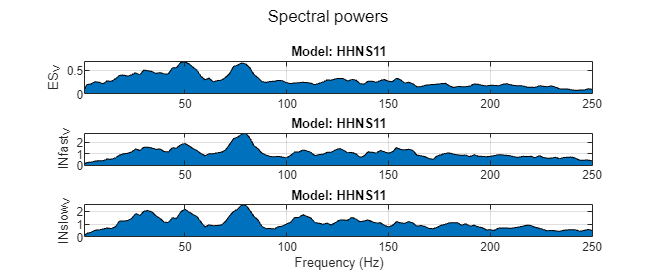

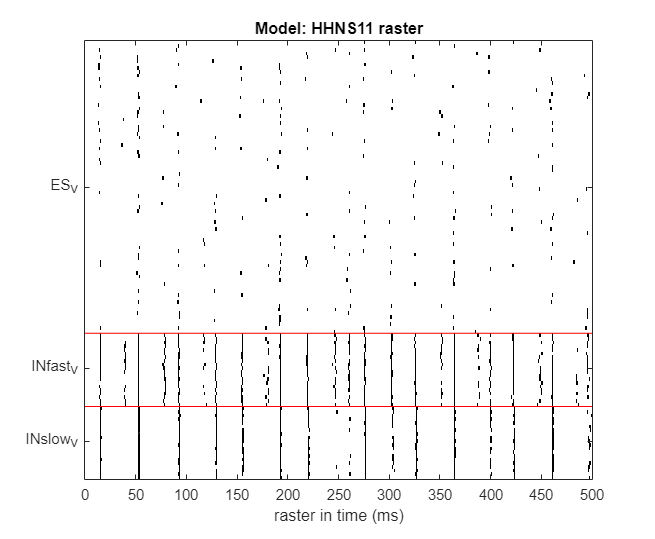

Condition2



	->Single trial running: 
Updating parameters of dlModels/HHNS11/solve > 
Done.

	-->Simulation outputs:     {[25.0204]}    {[-63.0606]}    {[-59.4528]}




--->No limit set or bad format:
---->opts map should have opts("lf") and opts("hf") as real positive values.

--->Default lf/hf = 1.0Hz/150.0HzTemp edit for q subplots; average fft


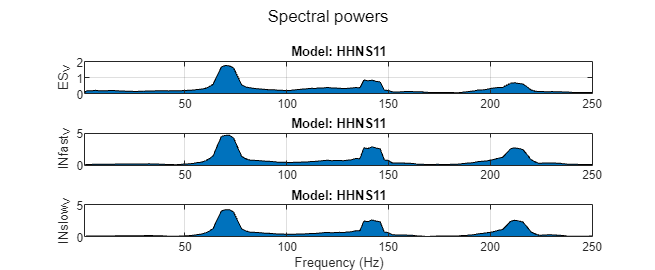

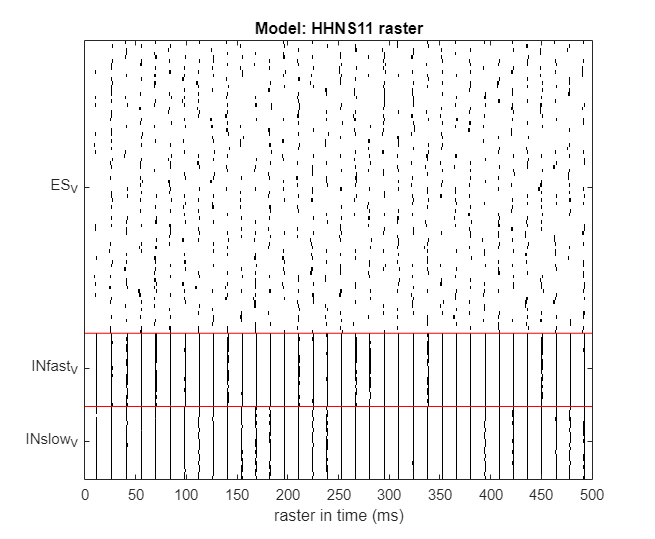

for i = 1:max(size(dlInputParameters, 1))

    disp("Condition" + num2str(i));
    dl.dlRunSimulation(dlInputParameters{i}, dlOutputParameters);
    dl.dlPlotAllPotentials('avgfft');
    dl.dlPlotAllPotentials('raster');

end

fprintf("Initial aFR: %f, AV: ES = %f, INfast = %f\n", dl.dlLastOutputs{1}, dl.dlLastOutputs{2}, dl.dlLastOutputs{3});

Initial aFR: 25.020404, AV: ES = -63.060634, INfast = -59.452792


dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1e-3; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 10; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.0;

dlTrainOptions('dlExcludeDiverge') = 0; % Exclude non-optimals from model log
dlTrainOptions('dlCheckpointLengthCap') = 11;
dlTrainOptions('dlUpdateVerbose') = 1;
dlTrainOptions('dlTrainIncludeList') = ["ES_wContext", "INfast_wContext", "INslow_wContext"];

dlTrainOptions('dlTrainRestrictList') = ["ES_wContext", "INfast_wContext", "INslow_wContext"]; % Restrict list
dlTrainOptions('dlTrainRestrictCoef') = {1., 1., 1.}; % Restrict coeffs
dlTrainOptions('dlTrainRestrictBound') = {[-20 20], [-20 20], [-20 20]}; % Restrict boundary values (PDE)

dlTrainOptions('dlBatchs') = 2;
dlTrainOptions('dlUpdateMode') = 'batch';
dlTrainOptions('dlCheckpointCoefficient') = 1.2;

dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

-> Training started:

-->Included variable(s) on fitting: 
---> ES_wContext
---> INfast_wContext
---> INslow_wContext
-->Excluded variable(s) on fitting: 
-->No variables were manually excluded in the fitting exclude list.
--->No dynasim variables are excluded by default.
-->Restricted variable(s) on fitting: 
---> ES_wContext
---> INfast_wContext
---> INslow_wContext
-->Synchronized variable(s) on fitting: 
-->No variables were manually synchronized.
--->No dynasim variables are synchronized by default.
-->Learning rule was not determined in options map
--->Default dlLearningRule = 'GeneralizedStochasticDeltaRule'
-->No custom logs specified; Ignore this if you did not have custom logs.
-->Checkpoint flag was not determined in options map, default dlCheckpoint = 'true'
-->dlUpdateVerbose is 1 (On)
-->Adaptive lambda is active. Lambda (learning rate) will be changed based on volatility of model error.
--->Reminder: you have choosen adaptive lambda but forgot to determine a lambda cap. 

dl.dlPlotBatchErrors(dlTrainOptions('dlBatchs'));

dl.dlLoadOptimal();

		Checkpoint file loaded from dlModels/HHNS11/Optimal 
---->Optimal [Parallel]


dl.dlSimulate();

Done.


Condition1



	->Single trial running: 
Updating parameters of dlModels/HHNS11/solve > 
Done.

	-->Simulation outputs:     {[6.5038]}    {[-70.4234]}    {[-63.0830]}




--->No limit set or bad format:
---->opts map should have opts("lf") and opts("hf") as real positive values.

--->Default lf/hf = 1.0Hz/150.0HzTemp edit for q subplots; average fft


Condition2



	->Single trial running: 
Updating parameters of dlModels/HHNS11/solve > 
Done.

	-->Simulation outputs:     {[0]}    {[-89.2443]}    {[-57.1724]}




--->No limit set or bad format:
---->opts map should have opts("lf") and opts("hf") as real positive values.

--->Default lf/hf = 1.0Hz/150.0HzTemp edit for q subplots; average fft


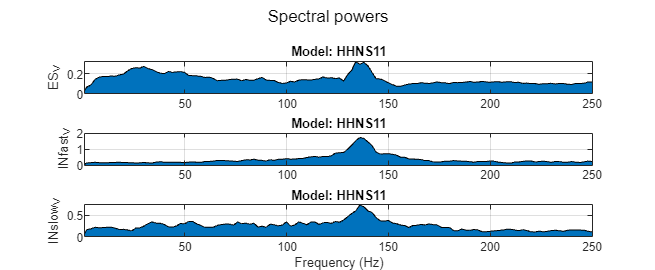

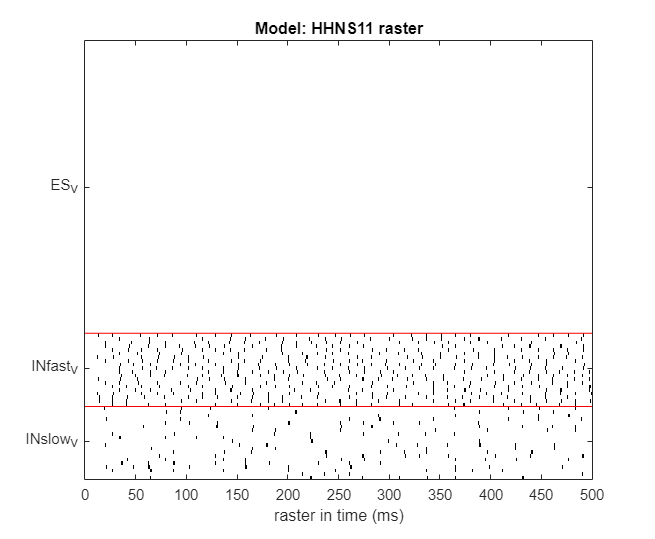

for i = 1:max(size(dlInputParameters, 1))

    disp("Condition" + num2str(i));
    dl.dlRunSimulation(dlInputParameters{i}, dlOutputParameters);
    dl.dlPlotAllPotentials('avgfft');
    dl.dlPlotAllPotentials('raster');

end

fprintf("Final aFR: %f, AV: ES = %f, INfast = %f\n", dl.dlLastOutputs{1}, dl.dlLastOutputs{2}, dl.dlLastOutputs{3});

Final aFR: 0.000000, AV: ES = -89.244345, INfast = -57.172351


optimal_param_file = fullfile(study_dir, 'Optimalparams.mat');
load(optimal_param_file, 'p');fprintf('Final W(E): %g, W(INf) = %g, W(INs) = %g\n', p.ES_wContext, p.INfast_wContext, p.INslow_wContext);

Final W(E): -20, W(INf) = 20, W(INs) = 20


## 3.3: Transition on single to multiple response optimization


$$:C_{i}?C_{p} \rightarrow f( [N] \frac{\beta_{8-30Hz}}{\gamma_{40-90Hz}} < [C_{P};C_{i}] \frac{\beta_{8-30Hz}}{\gamma_{40-90Hz}}; \nabla I_{app}, Tau_D, Noise)$$


RunDuration = 500; % In ms (miliseconds)
study_dir = 'dlModels/HHNS6';

eqns={
  'dV/dt=Iapp+@current+noise*randn(1,N_pop); Iapp=0; noise=0'
};

Iapp = 10;

gGABAfast = .1;
gAMPA = .1;

tauGABAfast = 5;
tauAMPA = 2;

s=[];
s.populations(1).name='ES';
s.populations(1).size=80;
s.populations(1).equations=eqns;
s.populations(1).mechanism_list={'iNa','iK'};
s.populations(1).parameters={'Iapp',Iapp,'gNa',120,'gK',36,'noise', 40};

s.populations(2).name='INf';
s.populations(2).size=20;
s.populations(2).equations=eqns;
s.populations(2).mechanism_list={'iNa','iK'};
s.populations(2).parameters={'Iapp',0,'gNa',120,'gK',36,'noise', 40};

s.populations(2).name='INs';
s.populations(2).size=20;
s.populations(2).equations=eqns;
s.populations(2).mechanism_list={'iNa','iK'};
s.populations(2).parameters={'Iapp',0,'gNa',120,'gK',36,'noise', 40};

s.connections(1).direction='INfast->ES';
s.connections(1).mechanism_list={'iGABAa'};
s.connections(1).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast};

s.connections(2).direction='ES->INfast';
s.connections(2).mechanism_list={'iAMPA'};
s.connections(2).parameters={'tauD',tauAMPA,'gAMPA',gAMPA};

s.connections(3).direction='INfast->INfast';
s.connections(3).mechanism_list={'iGABAa'};
s.connections(3).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast};

## Passing to DynaLearn

dl = DynaLearn(s, study_dir, 'mex', 'HHNS6', 1);
dl.dlSave();

## Load (ONLY IF ALREADY EXISTS)

id = 6; % 1, 2, ...
dl = DynaLearn.dlLoader(char("dlModels/HHNS" + num2str(id)));

param_file = fullfile(study_dir, 'params.mat');
load(param_file, 'p');
fprintf('Initial TauD(IN): %g, ES_Noise = %g, INF_Noise = %g\n', p.ES_INfast_iGABAa_tauD, p.ES_noise, p.INfast_noise);
target_FRQ = 25; % Hz
target_FRQ2 = 40; % mV

dlInputParameters = {dlNullInputs(RunDuration)}; % Null inputs (no external stimulation).
dlOutputParameters = [{['ES', '_V'], 1:80, [10 RunDuration], 'afr'}; {['ES', '_V'], 1:80, [10 RunDuration], 'av'}; {['INfast', '_V'], 1:20, [10 RunDuration], 'av'}];
dlTargetParameters = {{'QRPenalty', 1, 7., 1., 20, 40, 55, 75}; {'MSE', 2, -60, 1}; {'MSE', 3, -60, 1}}; % Format: (1)Mode;(2)Output indices;(3)Target value;(4)Weight in loss equation

% Define training options
dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1e-5; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 1; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.4;

dlTrainOptions('dlExcludeDiverge') = 0; % Exclude non-optimals from model log
dlTrainOptions('dlCheckpointLengthCap') = 11;
dlTrainOptions('dlUpdateVerbose') = 1;
dlTrainOptions('dlTrainIncludeList') = ["ES_INfast_iGABAa_tauD", "ES_noise", "INfast_noise"];

dlTrainOptions('dlTrainRestrictList') = ["ES_noise", "INfast_noise"]; % Restrict list
dlTrainOptions('dlTrainRestrictCoef') = {.1, .1}; % Restrict coeffs
dlTrainOptions('dlTrainSyncList') = ["ES_INfast_iGABAa_tauD", ...
    "INfast_INfast_iGABAa_tauD"]; % Each array row will be overrided
                                  % by synchronizing to the first element
dlTrainOptions('dlCheckpointCoefficient') = 1.2;

dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);
dl.dlSimulate();
dl.dlPlotAllPotentials('raster');
fprintf("Initial aFR: %f, AV: ES = %f, INfast = %f\n", dl.dlLastOutputs{1}, dl.dlLastOutputs{2}, dl.dlLastOutputs{3});

dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1e-2; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 30; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.1;

dlTrainOptions('dlExcludeDiverge') = 0; % Exclude non-optimals from model log
dlTrainOptions('dlCheckpointLengthCap') = 11;
dlTrainOptions('dlUpdateVerbose') = 1;
dlTrainOptions('dlTrainIncludeList') = ["ES_INfast_iGABAa_tauD", "ES_noise", "INfast_noise"];

dlTrainOptions('dlTrainRestrictList') = ["ES_noise", "INfast_noise"]; % Restrict list
dlTrainOptions('dlTrainRestrictCoef') = {0.1, 0.1}; % Restrict coeffs
dlTrainOptions('dlTrainSyncList') = ["ES_INfast_iGABAa_tauD", ...
    "INfast_INfast_iGABAa_tauD"]; % Each array row will be overrided
                                  % by synchronizing to the first element

dlTrainOptions('dlCheckpointCoefficient') = 1.2;

dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

dl.dlPlotBatchErrors(1);
dl.dlLoadOptimal();
dl.dlSimulate();
dl.dlPlotAllPotentials('raster');

fprintf("Final aFR: %f, AV: ES = %f, INfast = %f\n", dl.dlLastOutputs{1}, dl.dlLastOutputs{2}, dl.dlLastOutputs{3});
optimal_param_file = fullfile(study_dir, 'Optimalparams.mat');
load(optimal_param_file, 'p');
fprintf('Final TauD(IN): %g, ES_Noise = %g, INF_Noise = %g\n', p.ES_INfast_iGABAa_tauD, p.ES_noise, p.INfast_noise);

## END